clear; clc; close all;

% Tambahkan folder package ke path
addpath('/MATLAB Drive/MS_Regress-Matlab-master/m_Files');

% =========================================================
% BACA DATA
% =========================================================
dataTbl = readtable('/MATLAB Drive/fix_dataset_insyaAllah (1).csv');
dataTbl.Date = datetime(dataTbl.Date);

% Ambil kolom return
% Urutan variabel: [IHSG, Gold, BTC]
Yraw = [double(dataTbl.ihsg), double(dataTbl.gold), double(dataTbl.btc)];

% Hapus baris yang mengandung NaN atau Inf
idxValid = all(isfinite(Yraw), 2);
Y     = Yraw(idxValid, :);
dates = dataTbl.Date(idxValid);

% =========================================================
% SPESIFIKASI DASAR
% =========================================================
dep_raw = Y;

nLag = 1;     % MS-IH-VAR(1)
k    = 2;     % jumlah rezim

[nT, nVar] = size(dep_raw);

if nVar ~= 3
    error('Y harus memiliki 3 kolom: [ihsg gold btc]');
end

if nT <= nLag
    error('Jumlah observasi terlalu sedikit untuk nLag = %d.', nLag);
end

varNames = {'IHSG','Gold','BTC'};
eqNames  = {'IHSG','GOLD','BTC'};

% =========================================================
% MEMBENTUK DEPENDENT DAN LAG VAR(1)
% =========================================================
dep       = dep_raw(nLag+1:end, :);     % Y_t
dates_eff = dates(nLag+1:end);          % tanggal efektif
nObs      = size(dep,1);

% Matriks lag:
% Untuk nLag = 1:
% [ihsg(-1), gold(-1), btc(-1)]
Xlag = [];

for L = 1:nLag
    Xlag = [Xlag dep_raw(nLag+1-L:end-L, :)];
end

% Regressor:
% [const, ihsg(-1), gold(-1), btc(-1)]
X = [ones(nObs,1), Xlag];

indep = cell(1, nVar);
for eq = 1:nVar
    indep{eq} = X;
end

nReg = size(X,2);
expectedReg = 1 + nVar*nLag;

if nReg ~= expectedReg
    error('Jumlah regressor tidak sesuai. Harus %d, tetapi terbentuk %d.', ...
        expectedReg, nReg);
end

fprintf('\n=========================================================\n');

fprintf('INFORMASI SPESIFIKASI MODEL\n');

INFORMASI SPESIFIKASI MODEL


fprintf('=========================================================\n');

fprintf('Model                  : MS-IH-VAR(%d)\n', nLag);

Model                  : MS-IH-VAR(1)


fprintf('Jumlah variabel         : %d\n', nVar);

Jumlah variabel         : 3


fprintf('Jumlah lag VAR          : %d\n', nLag);

Jumlah lag VAR          : 1


fprintf('Jumlah observasi awal   : %d\n', nT);

Jumlah observasi awal   : 2346


fprintf('Jumlah observasi efektif: %d\n', nObs);

Jumlah observasi efektif: 2345


fprintf('Jumlah regressor        : %d\n', nReg);

Jumlah regressor        : 4


fprintf('Panjang S vector        : %d\n', nReg + 1);

Panjang S vector        : 5



% =========================================================
% ADVANCED OPTIONS
% =========================================================
advOpt.distrib    = 'Normal';
advOpt.std_method = 1;
advOpt.diagCovMat = 0;      % full variance-covariance matrix
advOpt.printOut   = 1;
advOpt.printIter  = 1;
advOpt.doPlots    = 1;
advOpt.optimizer  = 'fminsearch';

% =========================================================
% SPESIFIKASI MODEL MS-IH-VAR(1)
% =========================================================
% Struktur S vector:
% [intercept, ihsg(-1), gold(-1), btc(-1), covariance]
%
% MS-IH:
% intercept switching          = 1
% AR coefficient switching     = 0
% covariance switching         = 1
%
% Maka Svec = [1 0 0 0 1]
% =========================================================

Svec = zeros(1, nReg + 1);

% Intercept switching
Svec(1) = 1;

% AR coefficients non-switching
Svec(2:nReg) = 0;

% Variance-covariance switching
Svec(nReg + 1) = 1;

S = cell(1, nVar);
for eq = 1:nVar
    S{eq} = Svec;
end

fprintf('\n=========================================================\n');

fprintf('ESTIMASI MODEL MS-IH-VAR(%d)\n', nLag);

ESTIMASI MODEL MS-IH-VAR(1)


fprintf('=========================================================\n');

fprintf('S vector = [%s]\n', num2str(Svec));

S vector = [1  0  0  0  1]


fprintf('Keterangan: [intercept switching, AR non-switching, covariance switching]\n');

Keterangan: [intercept switching, AR non-switching, covariance switching]



Sum log likelihood for MS Model -> -12347.1861
Sum log likelihood for MS Model -> -12358.6983
Sum log likelihood for MS Model -> -12347.1652
Sum log likelihood for MS Model -> -12354.7778
Sum log likelihood for MS Model -> -12347.2163
Sum log likelihood for MS Model -> -12347.1846
Sum log likelihood for MS Model -> -12356.8788
Sum log likelihood for MS Model -> -12335.2921
Sum log likelihood for MS Model -> -12347.2082
Sum log likelihood for MS Model -> -12338.0372
Sum log likelihood for MS Model -> -12347.2055
Sum log likelihood for MS Model -> -12347.189
Sum log likelihood for MS Model -> -12336.5067
Sum log likelihood for MS Model -> -12347.1995
Sum log likelihood for MS Model -> -12347.1884
Sum log likelihood for MS Model -> -12347.2027
Sum log likelihood for MS Model -> -12347.1829
Sum log likelihood for MS Model -> -12347.1955
Sum log likelihood for MS Model -> -12347.2999
Sum log likelihood for MS Model -> -12347.1878
Sum log likelihood for MS Model -> -12347.2008
Sum log likel

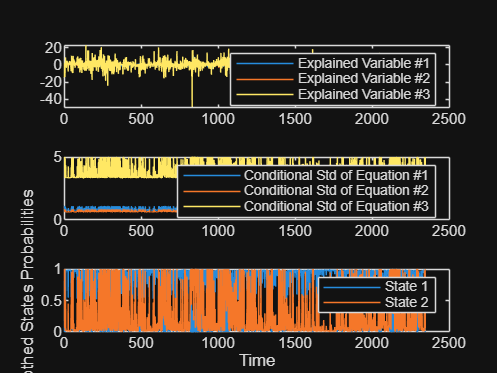

 


***** Numerical Optimization Converged *****

Final log Likelihood: -11760.7438
Number of estimated parameters: 29
Number of Observations: 2345
Number of Equations: 3
Optimizer: fminsearch
Type of Switching Model: Multivariate
Number of Equations in System: 3
Distribution Assumption -> Normal
Method SE calculation -> 1

***** Final Parameters for Equation #1 ***** 

---> Non Switching Parameters <---

Non Switching Parameter for Equation #1, Indep column 2 
     Value:                0.0088
     Std Error (p. value): 0.0301 (0.77)
Non Switching Parameter for Equation #1, Indep column 3 
     Value:                -0.0110
     Std Error (p. value): 0.0263 (0.68)
Non Switching Parameter for Equation #1, Indep column 4 
     Value:                0.0077
     Std Error (p. value): 0.0042 (0.07)

--->   Switching Parameters (Distribution Parameters)  <---

State 1
    Model's Variance:      0.359621
    Std Error (p. value):  0.0245 (0.00)
State 2
    Model's Variance:      2.454577
   


Spec_IH = MS_Regress_Fit(dep, indep, k, S, advOpt);


% =========================================================
% RINGKASAN HASIL MODEL
% =========================================================
BestModel  = Spec_IH;
model_name = 'MS-IH-VAR(1)';

fprintf('\n=========================================================\n');

fprintf('RINGKASAN HASIL MODEL %s\n', model_name);

RINGKASAN HASIL MODEL MS-IH-VAR(1)


fprintf('=========================================================\n');

fprintf('LL  = %.4f\n', BestModel.LL);

LL  = -11760.7438


fprintf('AIC = %.4f\n', BestModel.AIC);

AIC = 23579.4876


fprintf('BIC = %.4f\n', BestModel.BIC);

BIC = 23778.3885



% =========================================================
% TRANSITION PROBABILITY MATRIX
% =========================================================
P = BestModel.Coeff.p;

disp('=== TRANSITION PROBABILITY MATRIX ===');

=== TRANSITION PROBABILITY MATRIX ===


disp(P);

    0.8351    0.4835
    0.1649    0.5165




TransitionTable = array2table(P, ...
    'VariableNames', {'To_Regime1','To_Regime2'}, ...
    'RowNames', {'From_Regime1','From_Regime2'});

disp('=== TRANSITION PROBABILITY MATRIX TABLE ===');

=== TRANSITION PROBABILITY MATRIX TABLE ===


disp(TransitionTable);

                    To_Regime1    To_Regime2
                    __________    __________

    From_Regime1     0.83506       0.48346  
    From_Regime2     0.16494       0.51654  




% =========================================================
% EXPECTED DURATION
% =========================================================
dur = BestModel.stateDur;

disp('=== EXPECTED DURATION OF REGIMES ===');

=== EXPECTED DURATION OF REGIMES ===


for s = 1:length(dur)
    fprintf('Regime %d : %.4f hari observasi\n', s, dur(s));
end

Regime 1 : 6.0628 hari observasi
Regime 2 : 2.0684 hari observasi



DurationTable = table(dur(1), dur(2), ...
    'VariableNames', {'Regime1','Regime2'});

disp('=== EXPECTED DURATION TABLE ===');

=== EXPECTED DURATION TABLE ===


disp(DurationTable);

    Regime1    Regime2
    _______    _______

    6.0628     2.0684 




% =========================================================
% FILTERED & SMOOTHED PROBABILITIES
% =========================================================
filtProb   = BestModel.filtProb;
smoothProb = BestModel.smoothProb;

% Samakan panjang
minLen = min([length(dates_eff), size(dep,1), size(smoothProb,1)]);
dates_eff  = dates_eff(1:minLen);
dep        = dep(1:minLen, :);
smoothProb = smoothProb(1:minLen, :);
filtProb   = filtProb(1:minLen, :);

disp('=== UKURAN PROBABILITAS ===');

=== UKURAN PROBABILITAS ===


fprintf('Filtered Prob size : %d x %d\n', size(filtProb,1), size(filtProb,2));

Filtered Prob size : 2345 x 2


fprintf('Smoothed Prob size : %d x %d\n', size(smoothProb,1), size(smoothProb,2));

Smoothed Prob size : 2345 x 2



% =========================================================
% MOST LIKELY REGIME
% =========================================================
[~, regimePath] = max(smoothProb, [], 2);

disp('=== 10 OBSERVASI PERTAMA MOST LIKELY REGIME ===');

=== 10 OBSERVASI PERTAMA MOST LIKELY REGIME ===


disp(table(dates_eff(1:10), regimePath(1:10), ...
    'VariableNames', {'Date','Regime'}));

       Date       Regime
    __________    ______

    2017-01-05      2   
    2017-01-06      2   
    2017-01-09      1   
    2017-01-10      1   
    2017-01-11      2   
    2017-01-12      1   
    2017-01-13      1   
    2017-01-16      1   
    2017-01-17      2   
    2017-01-18      1   




% =========================================================
% TABEL HASIL REGIME
% =========================================================
Result_Regime = table( ...
    dates_eff, ...
    dep(:,1), dep(:,2), dep(:,3), ...
    smoothProb(:,1), smoothProb(:,2), ...
    regimePath, ...
    'VariableNames', {'Date','ihsg','gold','btc', ...
    'Prob_Regime1','Prob_Regime2','MostLikelyRegime'} ...
);

disp('=== HASIL REGIME HEAD ===');

=== HASIL REGIME HEAD ===


disp(head(Result_Regime));

       Date         ihsg         gold        btc       Prob_Regime1    Prob_Regime2    MostLikelyRegime
    __________    _________    ________    ________    ____________    ____________    ________________

    2017-01-05      0.45772     0.16488     -14.579     5.0548e-06        0.99999             2        
    2017-01-06      0.40328    -0.16488     -11.178       0.001061        0.99894             2        
    2017-01-09     -0.57505    -0.66225      1.8073        0.91225        0.08775             1        
    2017-01-10     -0.12121      0.4971    0.023121          0.935       0.064999             1        
    2017-01-11      -0.1636           0     -14.055      7.336e-05        0.99993             2        
    2017-01-12     -0.16028     0


% =========================================================
% COVARIANCE MATRIX DAN CORRELATION MATRIX PER REZIM
% =========================================================
disp('=== COVARIANCE MATRIX PER REZIM ===');

=== COVARIANCE MATRIX PER REZIM ===



for s = 1:k
    fprintf('\nRegime %d\n', s);
    disp(BestModel.Coeff.covMat{s});
end


Regime 1


    0.3596    0.0215    0.0346
    0.0215    0.2858   -0.0108
    0.0346   -0.0108    6.3712




Regime 2


    2.4546   -0.0063    0.7133
   -0.0063    1.2862    0.0038
    0.7133    0.0038   53.5381




disp('=== CORRELATION MATRIX PER REZIM ===');

=== CORRELATION MATRIX PER REZIM ===



for s = 1:k
    COV_s  = BestModel.Coeff.covMat{s};
    CORR_s = corrcov(COV_s);

    fprintf('\nRegime %d\n', s);
    disp(array2table(CORR_s, ...
        'VariableNames', {'ihsg','gold','btc'}, ...
        'RowNames', {'ihsg','gold','btc'}));
end


Regime 1


              ihsg         gold          btc    
            ________    __________    __________

    ihsg           1      0.066985      0.022846
    gold    0.066985             1    -0.0080015
    btc     0.022846    -0.0080015             1




Regime 2


               ihsg          gold          btc    
            __________    __________    __________

    ihsg             1    -0.0035626      0.062223
    gold    -0.0035626             1    0.00045786
    btc       0.062223    0.00045786             1




% =========================================================
% IDENTIFIKASI REZIM BERDASARKAN VOLATILITAS
% =========================================================
vol_measure = zeros(k,1);

for s = 1:k
    COV_s = BestModel.Coeff.covMat{s};
    vol_measure(s) = trace(COV_s);
end

disp('=== UKURAN VOLATILITAS PER REZIM: TRACE COVARIANCE ===');

=== UKURAN VOLATILITAS PER REZIM: TRACE COVARIANCE ===


for s = 1:k
    fprintf('Regime %d : %.6f\n', s, vol_measure(s));
end

Regime 1 : 7.016632
Regime 2 : 57.278901



[~, crisisRegime] = max(vol_measure);
[~, normalRegime] = min(vol_measure);

fprintf('\nRegime volatilitas tertinggi = Regime %d, indikasi KRISIS\n', crisisRegime);


Regime volatilitas tertinggi = Regime 2, indikasi KRISIS


fprintf('Regime volatilitas terendah  = Regime %d, indikasi NORMAL\n', normalRegime);

Regime volatilitas terendah  = Regime 1, indikasi NORMAL



RegimeLabel = strings(size(regimePath));
RegimeLabel(regimePath == normalRegime) = "Normal";
RegimeLabel(regimePath == crisisRegime) = "Krisis";

Result_Regime.RegimeLabel = RegimeLabel;

disp('=== HASIL REGIME DENGAN LABEL ===');

=== HASIL REGIME DENGAN LABEL ===


disp(head(Result_Regime));

       Date         ihsg         gold        btc       Prob_Regime1    Prob_Regime2    MostLikelyRegime    RegimeLabel
    __________    _________    ________    ________    ____________    ____________    ________________    ___________

    2017-01-05      0.45772     0.16488     -14.579     5.0548e-06        0.99999             2             "Krisis"  
    2017-01-06      0.40328    -0.16488     -11.178       0.001061        0.99894             2             "Krisis"  
    2017-01-09     -0.57505    -0.66225      1.8073        0.91225        0.08775             1             "Normal"  
    2017-01-10     -0.12121      0.4971    0.023121          0.935       0.064999             1             "Normal"  
    2017-01-1


% =========================================================
% JUMLAH OBSERVASI PER REZIM
% =========================================================
fprintf('\n=== JUMLAH OBSERVASI PER REZIM ===\n');


=== JUMLAH OBSERVASI PER REZIM ===


for s = 1:k
    fprintf('Regime %d : %d observasi\n', s, sum(regimePath == s));
end

Regime 1 : 1849 observasi
Regime 2 : 496 observasi



fprintf('\n=== JUMLAH OBSERVASI NORMAL/KRISIS ===\n');


=== JUMLAH OBSERVASI NORMAL/KRISIS ===


fprintf('Normal : %d observasi\n', sum(Result_Regime.RegimeLabel == "Normal"));

Normal : 1849 observasi


fprintf('Krisis : %d observasi\n', sum(Result_Regime.RegimeLabel == "Krisis"));

Krisis : 496 observasi



% =========================================================
% STATISTIK DESKRIPTIF PER REZIM
% =========================================================
assetNames = {'ihsg','gold','btc'};
Desc = table();

for s = 1:k
    idx = regimePath == s;

    for j = 1:nVar
        temp = table( ...
            s, ...
            string(assetNames{j}), ...
            mean(dep(idx,j), 'omitnan'), ...
            std(dep(idx,j), 'omitnan'), ...
            min(dep(idx,j)), ...
            max(dep(idx,j)), ...
            sum(idx), ...
            'VariableNames', {'Regime','Variable','Mean','StdDev','Min','Max','N'} ...
        );

        Desc = [Desc; temp];
    end
end

disp('=== STATISTIK DESKRIPTIF PER REZIM ===');

=== STATISTIK DESKRIPTIF PER REZIM ===


disp(Desc);

    Regime    Variable      Mean       StdDev       Min       Max       N  
    ______    ________    _________    _______    _______    ______    ____

      1        "ihsg"      0.047663    0.59021    -1.9119    1.8567    1849
      1        "gold"      0.037121    0.54013    -1.7858    1.6246    1849
      1        "btc"        0.19782     2.4971    -7.9654    8.3028    1849
      2        "ihsg"     -0.079034     1.7077    -8.2319    9.7042     496
      2        "gold"       0.14742     1.2273     -7.383    6.4539     496
      2        "btc"        0.18501     8.0421    -48.569     22.88     496




% =========================================================
% STATISTIK DESKRIPTIF NORMAL/KRISIS
% =========================================================
Desc_Label = table();

for lab = ["Normal","Krisis"]
    idx = Result_Regime.RegimeLabel == lab;

    for j = 1:nVar
        temp = table( ...
            lab, ...
            string(assetNames{j}), ...
            mean(dep(idx,j), 'omitnan'), ...
            std(dep(idx,j), 'omitnan'), ...
            min(dep(idx,j)), ...
            max(dep(idx,j)), ...
            sum(idx), ...
            'VariableNames', {'RegimeLabel','Variable','Mean','StdDev','Min','Max','N'} ...
        );

        Desc_Label = [Desc_Label; temp];
    end
end

disp('=== STATISTIK DESKRIPTIF NORMAL/KRISIS ===');

=== STATISTIK DESKRIPTIF NORMAL/KRISIS ===


disp(Desc_Label);

    RegimeLabel    Variable      Mean       StdDev       Min       Max       N  
    ___________    ________    _________    _______    _______    ______    ____

     "Normal"       "ihsg"      0.047663    0.59021    -1.9119    1.8567    1849
     "Normal"       "gold"      0.037121    0.54013    -1.7858    1.6246    1849
     "Normal"       "btc"        0.19782     2.4971    -7.9654    8.3028    1849
     "Krisis"       "ihsg"     -0.079034     1.7077    -8.2319    9.7042     496
     "Krisis"       "gold"       0.14742     1.2273     -7.383    6.4539     496
     "Krisis"       "btc"        0.18501     8.0421    -48.569     22.88     496



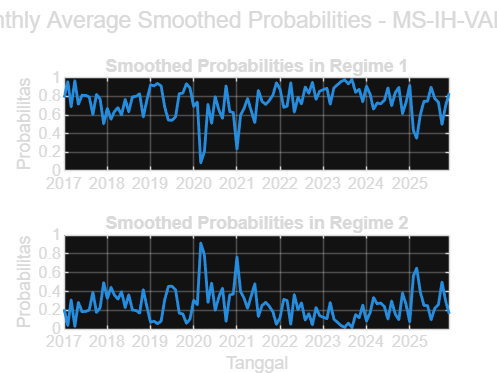


% =========================================================
% PLOT SMOOTHED PROBABILITIES RATA-RATA BULANAN
% =========================================================
TT = timetable(dates_eff, smoothProb(:,1), smoothProb(:,2), ...
    'VariableNames', {'Regime1','Regime2'});

TT_monthly = retime(TT, 'monthly', 'mean');
monthlyDates = TT_monthly.dates_eff;

figure('Name','Monthly Smoothed Probabilities','Color','w');

subplot(2,1,1);
plot(monthlyDates, TT_monthly.Regime1, 'LineWidth', 1.5);
ylim([0 1]);
yticks(0:0.2:1);
xlim([min(monthlyDates) max(monthlyDates)]);
grid on;
ylabel('Probabilitas');
title('Smoothed Probabilities in Regime 1');
xtickformat('yyyy');

subplot(2,1,2);
plot(monthlyDates, TT_monthly.Regime2, 'LineWidth', 1.5);
ylim([0 1]);
yticks(0:0.2:1);
xlim([min(monthlyDates) max(monthlyDates)]);
grid on;
xlabel('Tanggal');
ylabel('Probabilitas');
title('Smoothed Probabilities in Regime 2');
xtickformat('yyyy');

sgtitle(['Monthly Average Smoothed Probabilities - ', model_name]);

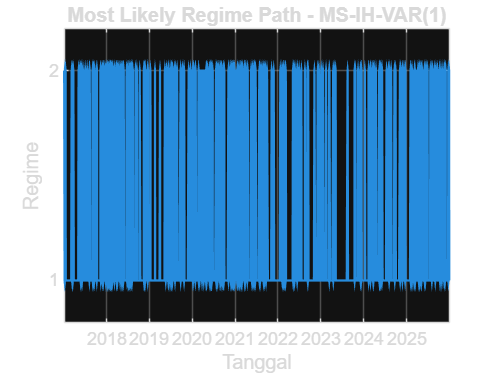


% =========================================================
% PLOT MOST LIKELY REGIME PATH
% =========================================================
figure('Name','Most Likely Regime','Color','w');

stairs(dates_eff, regimePath, 'LineWidth', 1.2);
grid on;
ylim([0.8, 2.2]);
yticks([1 2]);
xlabel('Tanggal');
ylabel('Regime');
title(['Most Likely Regime Path - ', model_name]);

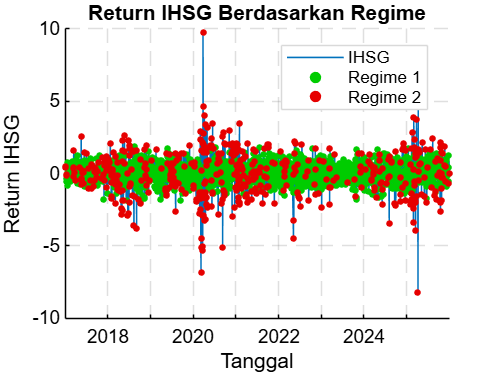

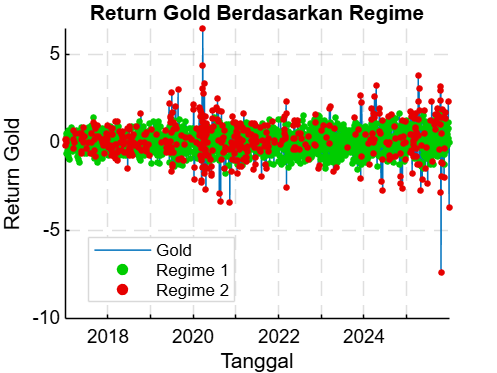

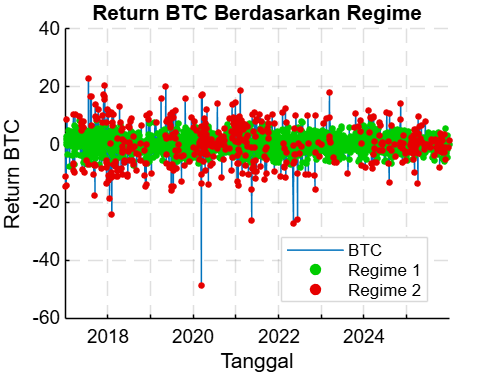


% =========================================================
% PLOT RETURN BERDASARKAN REGIME - LATAR PUTIH
% =========================================================
for j = 1:nVar

    figure('Name',[varNames{j}, ' by Regime'], 'Color','w');
    hold on;

    % Plot return utama
    plot(dates_eff, dep(:,j), '-', ...
        'LineWidth', 0.8, ...
        'Color', [0 0.4470 0.7410]);

    % Scatter berdasarkan regime
    scatter(dates_eff(regimePath==1), dep(regimePath==1,j), ...
        12, ...
        [0 0.8 0], ...
        'filled');

    scatter(dates_eff(regimePath==2), dep(regimePath==2,j), ...
        12, ...
        [0.9 0 0], ...
        'filled');

    grid on;

    xlabel('Tanggal', 'Color', 'k');
    ylabel(['Return ', varNames{j}], 'Color', 'k');
    title(['Return ', varNames{j}, ' Berdasarkan Regime'], 'Color', 'k');

    legend(varNames{j}, 'Regime 1','Regime 2', ...
        'Location','best', ...
        'TextColor','k', ...
        'Color','w');

    % Paksa latar plot putih dan font hitam
    ax = gca;
    ax.Color = 'w';
    ax.XColor = 'k';
    ax.YColor = 'k';
    ax.GridColor = [0.5 0.5 0.5];
    ax.GridLineStyle = '--';
    ax.GridAlpha = 0.25;
    ax.FontSize = 10;

    hold off;
end

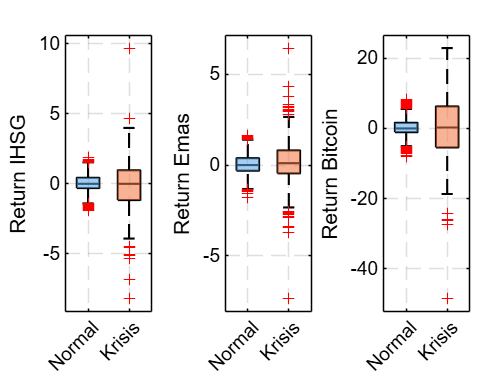

% =========================================================
% BOXPLOT RETURN BERDASARKAN NORMAL/KRISIS - LATAR PUTIH
% =========================================================

Tbox = Result_Regime;
Tbox.RegimeLabel = categorical(string(Tbox.RegimeLabel), ...
    ["Normal","Krisis"], ["Normal","Krisis"]);

warnaBox = [
    0.35 0.65 0.90;   % Normal
    0.95 0.45 0.25    % Krisis
    ];

figure('Name','Boxplot Return Berdasarkan Rezim','Color','w');

tiledlayout(1,3, ...
    'Padding','compact', ...
    'TileSpacing','compact');

% IHSG
nexttile;
boxWarna(Tbox.ihsg, Tbox.RegimeLabel, 'Return IHSG', warnaBox);

% EMAS
nexttile;
boxWarna(Tbox.gold, Tbox.RegimeLabel, 'Return Emas', warnaBox);

% BITCOIN
nexttile;
boxWarna(Tbox.btc, Tbox.RegimeLabel, 'Return Bitcoin', warnaBox);



% =========================================================
% FUNGSI
% =========================================================
function boxWarna(data, grup, labelY, warnaBox)

boxplot(data, grup, ...
    'Colors','k', ...
    'Symbol','r+', ...
    'Widths',0.55);

hold on;

% Warna isi box
hBox = findobj(gca, 'Tag', 'Box');
hBox = flipud(hBox);

for i = 1:length(hBox)
    patch(get(hBox(i), 'XData'), ...
        get(hBox(i), 'YData'), ...
        warnaBox(i,:), ...
        'FaceAlpha',0.55, ...
        'EdgeColor','none');
end

% Garis hitam dan outlier merah
hLine = findobj(gca, 'Type', 'Line');

for j = 1:length(hLine)
    if strcmp(get(hLine(j), 'Tag'), 'Outliers')
        set(hLine(j), ...
            'Color','r', ...
            'MarkerEdgeColor','r', ...
            'Marker','+');
    else
        set(hLine(j), ...
            'Color','k', ...
            'LineWidth',1.1);
    end
end

grid on;
xlabel('Rezim', 'Color','k');
ylabel(labelY, 'Color','k');

ax = gca;
ax.Color = 'w';
ax.XColor = 'k';
ax.YColor = 'k';
ax.GridColor = [0.5 0.5 0.5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.25;
ax.FontSize = 10;

set(findall(gca,'Type','text'), 'Color','k');

hold off;
end



% =========================================================
% EKSTRAK PARAMETER MS-IH
% =========================================================
% Model MS-IH:
% - Intercept switching
% - AR coefficient non-switching
% - Covariance switching
% =========================================================

[InterceptByRegime, A, LagCoefByEq] = extract_MSIH_params(BestModel, nVar, nLag, k);

disp('=== INTERCEPT SWITCHING PER REZIM ===');

=== INTERCEPT SWITCHING PER REZIM ===


InterceptTable = array2table(InterceptByRegime, ...
    'VariableNames', {'Regime1','Regime2'}, ...
    'RowNames', {'IHSG','Gold','BTC'});
disp(InterceptTable);

            Regime1     Regime2 
            ________    ________

    IHSG    0.044921    0.016247
    Gold    0.035096     0.10564
    BTC      0.19204    -0.27438




disp('=== KOEFISIEN LAG NON-SWITCHING ===');

=== KOEFISIEN LAG NON-SWITCHING ===


coefLagNames = {'ihsg(-1)','gold(-1)','btc(-1)'};

for eqIdx = 1:nVar
    tempLagTable = table( ...
        string(coefLagNames(:)), ...
        LagCoefByEq{eqIdx}(:), ...
        'VariableNames', {'Variable','Coefficient'} ...
    );

    fprintf('\nPersamaan %s\n', eqNames{eqIdx});
    disp(tempLagTable);
end


Persamaan IHSG


     Variable     Coefficient
    __________    ___________

    "ihsg(-1)"     0.0088333 
    "gold(-1)"     -0.011036 
    "btc(-1)"      0.0076732 




Persamaan GOLD


     Variable     Coefficient
    __________    ___________

    "ihsg(-1)"     -0.012879 
    "gold(-1)"     -0.014467 
    "btc(-1)"       0.017505 




Persamaan BTC


     Variable     Coefficient
    __________    ___________

    "ihsg(-1)"      -0.23692 
    "gold(-1)"       0.11407 
    "btc(-1)"      -0.035457 




% =========================================================
% UJI SIGNIFIKANSI PARAMETER NON-SWITCHING
% =========================================================
alpha = 0.05;

nObs_eff = size(dep,1);
nParamMean_eq = k + nVar*nLag;   % 2 intercept switching + 3 lag
df = nObs_eff - nParamMean_eq;

tTable = tinv(1 - alpha/2, df);

for eqIdx = 1:nVar

    fprintf('\n====================================================\n');
    fprintf('UJI SIGNIFIKANSI PARAMETER NON-SWITCHING - PERSAMAAN %s\n', eqNames{eqIdx});
    fprintf('====================================================\n');
    fprintf('t table alpha %.2f, df %d = %.4f\n', alpha, df, tTable);

    if isfield(BestModel, 'Coeff_SE') && isfield(BestModel.Coeff_SE, 'nS_Param')
        coef_NS = BestModel.Coeff.nS_Param{eqIdx}(:);
        se_NS   = BestModel.Coeff_SE.nS_Param{eqIdx}(:);
        pval_NS = BestModel.Coeff_pValues.nS_Param{eqIdx}(:);

        if numel(coef_NS) == nVar*nLag + 1
            coef_NS = coef_NS(2:end);
            se_NS   = se_NS(2:end);
            pval_NS = pval_NS(2:end);
        end

        tstat_NS = coef_NS ./ se_NS;
        TTable = repmat(tTable, numel(coef_NS), 1);

        Decision = strings(numel(pval_NS),1);
        Decision(abs(tstat_NS) > tTable)  = "Tolak H0";
        Decision(abs(tstat_NS) <= tTable) = "Gagal Tolak H0";

        Significance = strings(numel(pval_NS),1);
        Significance(pval_NS < 0.01) = "***";
        Significance(pval_NS >= 0.01 & pval_NS < 0.05) = "**";
        Significance(pval_NS >= 0.05 & pval_NS < 0.10) = "*";

        SigTable = table( ...
            string(coefLagNames(:)), ...
            coef_NS, ...
            se_NS, ...
            tstat_NS, ...
            TTable, ...
            pval_NS, ...
            Decision, ...
            Significance, ...
            'VariableNames', ...
            {'Variable','Coefficient','StdError','TStat','TTable','PValue','Decision','Significance'});

        disp(SigTable);
    else
        fprintf('Standard error/p-value tidak ditemukan pada struktur BestModel.\n');
    end
end

UJI SIGNIFIKANSI PARAMETER NON-SWITCHING - PERSAMAAN IHSG


t table alpha 0.05, df 2340 = 1.9610


     Variable     Coefficient    StdError      TStat      TTable     PValue         Decision        Significance
    __________    ___________    _________    ________    ______    ________    ________________    ____________

    "ihsg(-1)"     0.0088333      0.030145     0.29302    1.961      0.76953    "Gagal Tolak H0"        ""      
    "gold(-1)"     -0.011036      0.026332    -0.41912    1.961      0.67517    "Gagal Tolak H0"        ""      
    "btc(-1)"      0.0076732     0.0042496      1.8057    1.961     0.071101    "Gagal Tolak H0"        "*"     



UJI SIGNIFIKANSI PARAMETER NON-SWITCHING - PERSAMAAN GOLD


t table alpha 0.05, df 2340 = 1.9610


     Variable     Coefficient    StdError      TStat      TTable      PValue          Decision        Significance
    __________    ___________    _________    ________    ______    __________    ________________    ____________

    "ihsg(-1)"     -0.012879      0.017689    -0.72809    1.961        0.46663    "Gagal Tolak H0"       ""       
    "gold(-1)"     -0.014467      0.020449     -0.7075    1.961        0.47933    "Gagal Tolak H0"       ""       
    "btc(-1)"       0.017505     0.0034438       5.083    1.961     4.0117e-07    "Tolak H0"             "***"    



UJI SIGNIFIKANSI PARAMETER NON-SWITCHING - PERSAMAAN BTC


t table alpha 0.05, df 2340 = 1.9610


     Variable     Coefficient    StdError     TStat     TTable     PValue          Decision        Significance
    __________    ___________    ________    _______    ______    _________    ________________    ____________

    "ihsg(-1)"      -0.23692     0.084708    -2.7969    1.961     0.0052028    "Tolak H0"             "***"    
    "gold(-1)"       0.11407      0.10039     1.1362    1.961       0.25598    "Gagal Tolak H0"       ""       
    "btc(-1)"      -0.035457     0.018751    -1.8909    1.961      0.058761    "Gagal Tolak H0"       "*"      




% =========================================================
% RESIDUAL MODEL
% =========================================================
resid = BestModel.resid;
resid = resid(1:min(size(resid,1), size(dep,1)), :);

[nResid, nVarResid] = size(resid);

disp('=== UKURAN RESIDUAL ===');

=== UKURAN RESIDUAL ===


fprintf('Jumlah observasi residual : %d\n', nResid);

Jumlah observasi residual : 2345


fprintf('Jumlah variabel           : %d\n', nVarResid);

Jumlah variabel           : 3



% =========================================================
% UJI JARQUE-BERA RESIDUAL
% =========================================================
df_JB = 2;
chiTable_JB = chi2inv(1 - alpha, df_JB);

JB_resid = table();

for j = 1:nVar
    x = resid(:,j);

    [h,pValue,jbStat,critVal] = jbtest(x, alpha);

    Decision = "Gagal Tolak H0";
    if h == 1
        Decision = "Tolak H0";
    end

    temp = table( ...
        string(varNames{j}), ...
        h, ...
        pValue, ...
        jbStat, ...
        chiTable_JB, ...
        critVal, ...
        Decision, ...
        'VariableNames', ...
        {'Variable','RejectH0','pValue','JBStat','ChiSquareTable','CriticalValue','Decision'} ...
    );

    JB_resid = [JB_resid; temp];
end

disp('=== UJI JARQUE-BERA RESIDUAL ===');

=== UJI JARQUE-BERA RESIDUAL ===


disp(JB_resid);

    Variable    RejectH0    pValue    JBStat    ChiSquareTable    CriticalValue     Decision 
    ________    ________    ______    ______    ______________    _____________    __________

     "IHSG"        1        0.001      13258        5.9915           5.9679        "Tolak H0"
     "Gold"        1        0.001     7739.7        5.9915           5.9679        "Tolak H0"
     "BTC"         1        0.001      13939        5.9915           5.9679        "Tolak H0"




% =========================================================
% UJI LJUNG-BOX RESIDUAL DAN RESIDUAL KUADRAT
% =========================================================
lagsToTest = [5 10 15 20];

LB_resid = table();
LB_resid_sq = table();

for j = 1:nVar
    x = resid(:,j);

    for L = lagsToTest
        [h,pValue,stat,cValue] = lbqtest(x, 'Lags', L);

        temp = table( ...
            string(varNames{j}), ...
            L, ...
            h, ...
            pValue, ...
            stat, ...
            cValue, ...
            'VariableNames', {'Variable','Lag','RejectH0','pValue','LBStat','CriticalValue'} ...
        );

        LB_resid = [LB_resid; temp];

        [h2,pValue2,stat2,cValue2] = lbqtest(x.^2, 'Lags', L);

        temp2 = table( ...
            string(varNames{j}), ...
            L, ...
            h2, ...
            pValue2, ...
            stat2, ...
            cValue2, ...
            'VariableNames', {'Variable','Lag','RejectH0','pValue','LBStat','CriticalValue'} ...
        );

        LB_resid_sq = [LB_resid_sq; temp2];
    end
end

disp('=== LJUNG-BOX RESIDUAL ===');

=== LJUNG-BOX RESIDUAL ===


disp(LB_resid);

    Variable    Lag    RejectH0      pValue      LBStat    CriticalValue
    ________    ___    ________    __________    ______    _____________

     "IHSG"      5      true       0.00049351    22.135        11.07    
     "IHSG"     10      true         0.005979    24.683       18.307    
     "IHSG"     15      true       1.7209e-06    55.096       24.996    
     "IHSG"     20      true       6.2001e-06    60.388        31.41    
     "Gold"      5      false         0.68055    3.1261        11.07    
     "Gold"     10      false          0.1517    14.492       18.307    
     "Gold"     15      false         0.13727    20.986       24.996    
     "Gold"     20      false        0.089118    28.931        31.41    
     "BTC"       5      false        0.092558    9.4456        11


disp('=== LJUNG-BOX RESIDUAL KUADRAT ===');

=== LJUNG-BOX RESIDUAL KUADRAT ===


disp(LB_resid_sq);

    Variable    Lag    RejectH0      pValue      LBStat    CriticalValue
    ________    ___    ________    __________    ______    _____________

     "IHSG"      5      true                0    508.77        11.07    
     "IHSG"     10      true                0    956.13       18.307    
     "IHSG"     15      true                0    1203.3       24.996    
     "IHSG"     20      true                0    1280.8        31.41    
     "Gold"      5      true                0    187.56        11.07    
     "Gold"     10      true                0    239.21       18.307    
     "Gold"     15      true                0    274.56       24.996    
     "Gold"     20      true                0    299.48        31.41    
     "BTC"       5      true       1.8252e-08     44.51        11


% =========================================================
% KORELASI DAN STATISTIK DESKRIPTIF RESIDUAL
% =========================================================
CorrResid = corrcoef(resid);

disp('=== KORELASI RESIDUAL ===');

=== KORELASI RESIDUAL ===


disp(array2table(CorrResid, ...
    'VariableNames', varNames, ...
    'RowNames', varNames));

              IHSG         Gold          BTC   
            _________    _________    _________

    IHSG            1    0.0057816      0.06938
    Gold    0.0057816            1    0.0012572
    BTC       0.06938    0.0012572            1




DescResid = table();

for j = 1:nVar
    x = resid(:,j);

    temp = table( ...
        string(varNames{j}), ...
        mean(x, 'omitnan'), ...
        std(x, 'omitnan'), ...
        min(x), ...
        max(x), ...
        skewness(x), ...
        kurtosis(x), ...
        'VariableNames', {'Variable','Mean','StdDev','Min','Max','Skewness','Kurtosis'} ...
    );

    DescResid = [DescResid; temp];
end

disp('=== STATISTIK DESKRIPTIF RESIDUAL ===');

=== STATISTIK DESKRIPTIF RESIDUAL ===


disp(DescResid);

    Variable      Mean       StdDev       Min       Max      Skewness     Kurtosis
    ________    _________    _______    _______    ______    _________    ________

     "IHSG"     -0.017798    0.94421    -8.2719    9.6647     -0.40121     14.621 
     "Gold"     0.0050434    0.73657    -7.3527     6.272    -0.024745       11.9 
     "BTC"        0.12705     4.3039    -48.889    22.589     -0.82124     14.831 



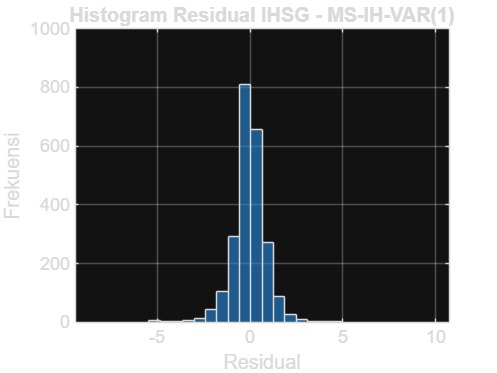

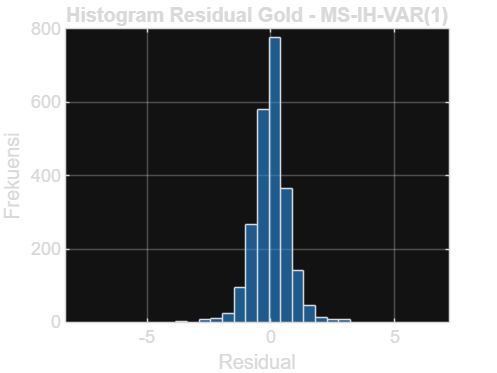

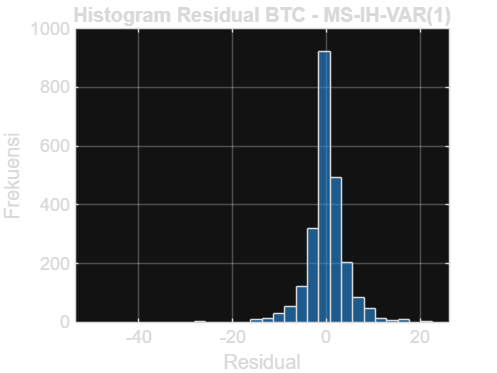


for j = 1:nVar
    figure('Name',['Histogram Residual ', varNames{j}], 'Color','w');
    histogram(resid(:,j), 30);
    grid on;
    xlabel('Residual');
    ylabel('Frekuensi');
    title(['Histogram Residual ', varNames{j}, ' - ', model_name]);
end


% =========================================================
% RINGKASAN DIAGNOSTIK RESIDUAL
% =========================================================
DiagSummary = table();

for j = 1:nVar
    x = resid(:,j);

    [~, pJB]     = jbtest(x);
    [~, pLB10]   = lbqtest(x, 'Lags', 10);
    [~, pLB20]   = lbqtest(x, 'Lags', 20);
    [~, pLBsq10] = lbqtest(x.^2, 'Lags', 10);
    [~, pLBsq20] = lbqtest(x.^2, 'Lags', 20);

    if pJB > alpha
        normText = "Residual normal";
    else
        normText = "Residual tidak normal";
    end

    if pLB10 > alpha && pLB20 > alpha
        autoText = "Tidak ada autokorelasi residual";
    else
        autoText = "Masih ada autokorelasi residual";
    end

    if pLBsq10 > alpha && pLBsq20 > alpha
        volText = "Tidak ada pola volatilitas tersisa";
    else
        volText = "Masih ada pola volatilitas tersisa";
    end

    temp = table( ...
        string(varNames{j}), ...
        pJB, ...
        pLB10, ...
        pLB20, ...
        pLBsq10, ...
        pLBsq20, ...
        normText, ...
        autoText, ...
        volText, ...
        'VariableNames', {'Variable','pValue_JB','pValue_LB10','pValue_LB20', ...
        'pValue_LBsq10','pValue_LBsq20','Normalitas','Autokorelasi','Volatilitas'} ...
    );

    DiagSummary = [DiagSummary; temp];
end

disp('=== RINGKASAN UJI DIAGNOSTIK RESIDUAL ===');

=== RINGKASAN UJI DIAGNOSTIK RESIDUAL ===


disp(DiagSummary);

    Variable    pValue_JB    pValue_LB10    pValue_LB20    pValue_LBsq10    pValue_LBsq20          Normalitas                     Autokorelasi                           Volatilitas             
    ________    _________    ___________    ___________    _____________    _____________    _______________________    _________________________________    ____________________________________

     "IHSG"       0.001       0.005979      6.2001e-06               0                0      "Residual tidak normal"    "Masih ada autokorelasi residual"    "Masih ada pola volatilitas tersisa"
     "Gold"       0.001         0.1517        0.089118               0                0      "Residual tidak no

% =========================================================
% RCM: REGIME CLASSIFICATION MEASURE
% =========================================================
P_smooth = smoothProb;
P_smooth = P_smooth(all(isfinite(P_smooth),2), :);

[T_prob, M] = size(P_smooth);

RCM = 100 * M^2 * mean(prod(P_smooth, 2));

fprintf('\n=== REGIME CLASSIFICATION MEASURE ===\n');


=== REGIME CLASSIFICATION MEASURE ===


fprintf('RCM = %.6f\n', RCM);

RCM = 30.446510



if RCM < 50
    fprintf('Klasifikasi rezim cukup baik karena RCM < 50.\n');
else
    fprintf('Klasifikasi rezim kurang baik karena RCM >= 50.\n');
end

Klasifikasi rezim cukup baik karena RCM < 50.



% =========================================================
% LR TEST PRAKTIS: VAR(1) BIASA VS MS-IH-VAR(1)
% =========================================================
% ---------------------------------------------------------
% 1) Estimasi model restricted: VAR(nLag) satu rezim
% ---------------------------------------------------------
Mdl_VAR = varm(nVar, nLag);

[EstMdl_VAR, EstSE_VAR, logL_VAR, E_VAR] = estimate( ...
    Mdl_VAR, ...
    Y, ...
    'Display', 'off' ...
);

% ---------------------------------------------------------
% 2) Ambil log-likelihood model unrestricted: MS-IH-VAR
% ---------------------------------------------------------
logL_MSIH = BestModel.LL;

% ---------------------------------------------------------
% 3) Tentukan derajat bebas praktis
% ---------------------------------------------------------
% Untuk MSIH(2)-VAR(1):
% I  = intercept switching
% H  = variance-covariance switching
% A  = koefisien autoregresif non-switching
%
% Tambahan parameter dibanding VAR biasa:
% - intercept tambahan antar rezim
% - covariance tambahan antar rezim
% - parameter transisi Markov

nRegime = 2;

nInterceptExtra = (nRegime - 1) * nVar;
nCovExtra       = (nRegime - 1) * nVar * (nVar + 1) / 2;
nTransParam     = nRegime * (nRegime - 1);

df_LR_praktis = nInterceptExtra + nCovExtra + nTransParam;

% ---------------------------------------------------------
% 4) LR test menggunakan library lratiotest
% ---------------------------------------------------------
% uLogL = log-likelihood unrestricted model = MS-IH-VAR
% rLogL = log-likelihood restricted model   = VAR satu rezim

[h_LR, pValue_LR, LR_stat, chiTable_LR] = lratiotest( ...
    logL_MSIH, ...
    logL_VAR, ...
    df_LR_praktis, ...
    alpha ...
);

% ---------------------------------------------------------
% 5) Keputusan
% ---------------------------------------------------------
if h_LR == 1
    Decision_LR = "Tolak H0";
else
    Decision_LR = "Gagal Tolak H0";
end

% ---------------------------------------------------------
% 6) Tabel hasil
% ---------------------------------------------------------
LR_Praktis = table( ...
    logL_VAR, ...
    logL_MSIH, ...
    LR_stat, ...
    df_LR_praktis, ...
    chiTable_LR, ...
    pValue_LR, ...
    Decision_LR, ...
    RCM, ...
    'VariableNames', {'LogL_VAR','LogL_MSIH_VAR','LR_Statistic', ...
                      'df_Praktis','ChiSquareTable','PValue', ...
                      'Decision','RCM'} ...
);

disp('=== LR TEST PRAKTIS VAR(1) VS MS-IH(2)-VAR(1) ===');

=== LR TEST PRAKTIS VAR(1) VS MS-IH(2)-VAR(1) ===


disp(LR_Praktis);

    LogL_VAR    LogL_MSIH_VAR    LR_Statistic    df_Praktis    ChiSquareTable    PValue     Decision      RCM  
    ________    _____________    ____________    __________    ______________    ______    __________    ______

     -12544        -11761           1565.8           11            19.675          0       "Tolak H0"    30.447




fprintf('\nCATATAN LR:\n');


CATATAN LR:


fprintf(['Uji LR ini menggunakan fungsi lratiotest dari Econometrics Toolbox. ', ...
         'Model restricted adalah VAR satu rezim, sedangkan model unrestricted ', ...
         'adalah MS-IH-VAR dua rezim. Karena pengujian Markov Switching dapat ', ...
         'berada pada kondisi nonstandard, hasil LR ini digunakan sebagai evaluasi ', ...
         'praktis/deskriptif untuk melihat peningkatan log-likelihood model MS-VAR ', ...
         'dibandingkan VAR biasa.\n']);

Uji LR ini menggunakan fungsi lratiotest dari Econometrics Toolbox. Model restricted adalah VAR satu rezim, sedangkan model unrestricted adalah MS-IH-VAR dua rezim. Karena pengujian Markov Switching dapat berada pada kondisi nonstandard, hasil LR ini digunakan sebagai evaluasi praktis/deskriptif untuk melihat peningkatan log-likelihood model MS-VAR dibandingkan VAR biasa.



% =========================================================
% JUMLAH HARI KRISIS PER BULAN 2017-2025
% =========================================================
T = Result_Regime;
T.RegimeLabel = string(T.RegimeLabel);
T.Date = datetime(T.Date);

idxPeriod = T.Date >= datetime(2017,1,1) & ...
            T.Date <= datetime(2025,12,31);

T_period = T(idxPeriod, :);

T_period.Year = year(T_period.Date);
T_period.Month = month(T_period.Date);
T_period.MonthName = string(month(T_period.Date, 'name'));
T_period.IsCrisis = T_period.RegimeLabel == "Krisis";
T_period.YearMonth = dateshift(T_period.Date, 'start', 'month');

uniqueMonth = unique(T_period.YearMonth);

MonthlyCrisis = table();

for i = 1:length(uniqueMonth)

    ym = uniqueMonth(i);
    idxMonth = T_period.YearMonth == ym;

    tahun = year(ym);
    bulan = month(ym);
    namaBulan = string(month(ym, 'name'));

    totalHariObservasi = sum(idxMonth);
    totalHariKrisis = sum(T_period.IsCrisis(idxMonth));
    totalHariNormal = totalHariObservasi - totalHariKrisis;

    persenKrisis = totalHariKrisis / totalHariObservasi * 100;

    temp = table( ...
        tahun, ...
        bulan, ...
        namaBulan, ...
        totalHariObservasi, ...
        totalHariNormal, ...
        totalHariKrisis, ...
        persenKrisis, ...
        'VariableNames', {'Tahun','Bulan','NamaBulan', ...
        'TotalHariObservasi','TotalHariNormal','TotalHariKrisis','PersentaseKrisis'} ...
    );

    MonthlyCrisis = [MonthlyCrisis; temp];
end

disp('=== JUMLAH HARI KRISIS PER BULAN 2017-2025 ===');

=== JUMLAH HARI KRISIS PER BULAN 2017-2025 ===


disp(MonthlyCrisis);

    Tahun    Bulan     NamaBulan     TotalHariObservasi    TotalHariNormal    TotalHariKrisis    PersentaseKrisis
    _____    _____    ___________    __________________    _______________    _______________    ________________

    2017       1      "January"              19                  15                  4                21.053     
    2017       2      "February"             20                  20                  0                     0     
    2017       3      "March"                23                  17                  6                26.087     
    2017       4      "April"                20                  20                  0                     0     
    2017       5      "May"                  23                  17          


fprintf('\n=== CEK TOTAL KRISIS ===\n');


=== CEK TOTAL KRISIS ===


fprintf('Total krisis dari tabel bulanan : %d hari\n', sum(MonthlyCrisis.TotalHariKrisis));

Total krisis dari tabel bulanan : 496 hari


fprintf('Total krisis dari Result_Regime : %d hari\n', sum(T_period.RegimeLabel == "Krisis"));

Total krisis dari Result_Regime : 496 hari



% =========================================================
% DURASI EPISODE KRISIS
% =========================================================
T = Result_Regime;
T.Date = datetime(T.Date);
T.RegimeLabel = string(T.RegimeLabel);

idxPeriod = T.Date >= datetime(2017,1,1) & ...
            T.Date <= datetime(2025,12,31);

T = T(idxPeriod, :);

isCrisis = T.RegimeLabel == "Krisis";

changeFlag = [true; isCrisis(2:end) ~= isCrisis(1:end-1)];
groupID = cumsum(changeFlag);

crisisGroups = unique(groupID(isCrisis));

EpisodeTable = table();

for i = 1:length(crisisGroups)

    g = crisisGroups(i);
    idxEpisode = groupID == g & isCrisis;

    startDate = min(T.Date(idxEpisode));
    endDate   = max(T.Date(idxEpisode));
    duration  = sum(idxEpisode);

    temp = table( ...
        g, ...
        startDate, ...
        endDate, ...
        duration, ...
        'VariableNames', {'EpisodeID','StartDate','EndDate','DurationDays'} ...
    );

    EpisodeTable = [EpisodeTable; temp];
end

disp('=== TABEL EPISODE KRISIS BERURUTAN ===');

=== TABEL EPISODE KRISIS BERURUTAN ===


disp(EpisodeTable);

    EpisodeID    StartDate      EndDate      DurationDays
    _________    __________    __________    ____________

         1       2017-01-05    2017-01-06          2     
         3       2017-01-11    2017-01-11          1     
         5       2017-01-17    2017-01-17          1     
         7       2017-03-10    2017-03-13          2     
         9       2017-03-16    2017-03-17          2     
        11       2017-03-24    2017-03-27          2     
        13       2017-05-08    2017-05-08          1     
        15       2017-05-19    2017-05-24          4     
        17       2017-05-26    2017-05-26          1     
        19       2017-06-02    2017-06-06          3     
        21       2017-06-14    2017-06-14          1     
        23       2017-07-03    2017-07-03          1     
        25       2017-07-20    2017-07-21          


nKrisis = sum(isCrisis);
nEpisode = height(EpisodeTable);

fprintf('\n=== RINGKASAN DURASI EMPIRIS EPISODE KRISIS ===\n');


=== RINGKASAN DURASI EMPIRIS EPISODE KRISIS ===


fprintf('Jumlah total hari krisis     : %d hari observasi\n', nKrisis);

Jumlah total hari krisis     : 496 hari observasi


fprintf('Jumlah episode krisis        : %d episode\n', nEpisode);

Jumlah episode krisis        : 258 episode


fprintf('Rata-rata durasi episode     : %.6f hari observasi\n', mean(EpisodeTable.DurationDays));

Rata-rata durasi episode     : 1.922481 hari observasi


fprintf('Median durasi episode        : %.6f hari observasi\n', median(EpisodeTable.DurationDays));

Median durasi episode        : 1.000000 hari observasi


fprintf('Durasi minimum episode       : %d hari observasi\n', min(EpisodeTable.DurationDays));

Durasi minimum episode       : 1 hari observasi


fprintf('Durasi maksimum episode      : %d hari observasi\n', max(EpisodeTable.DurationDays));

Durasi maksimum episode      : 13 hari observasi



EpisodeSorted = sortrows(EpisodeTable, 'DurationDays', 'descend');

disp('=== 15 EPISODE KRISIS TERPANJANG ===');

=== 15 EPISODE KRISIS TERPANJANG ===


disp(EpisodeSorted(1:min(15,height(EpisodeSorted)), :));

    EpisodeID    StartDate      EndDate      DurationDays
    _________    __________    __________    ____________

       197       2020-03-06    2020-03-24         13     
       199       2020-03-26    2020-04-08         10     
       201       2020-04-13    2020-04-24         10     
       263       2021-01-04    2021-01-15         10     
       503       2025-10-16    2025-10-28          9     
       153       2019-06-20    2019-07-01          8     
       459       2025-02-25    2025-03-05          7     
       465       2025-03-18    2025-03-26          7     
       145       2019-05-13    2019-05-20          6     
       195       2020-02-26    2020-03-04          6     
       267       2021-01-26    2021-02-02          6     
        53       2017-12-18    2017-12-22          5     
        93       2018-05-03    2018-05-09          


% Distribusi durasi episode
durasiUnik = unique(EpisodeTable.DurationDays);
DurasiDistribusi = table();

for i = 1:length(durasiUnik)

    d = durasiUnik(i);

    jumlahEpisode = sum(EpisodeTable.DurationDays == d);
    totalHariKrisis = d * jumlahEpisode;
    persentaseEpisode = jumlahEpisode / height(EpisodeTable) * 100;

    temp = table( ...
        d, ...
        jumlahEpisode, ...
        totalHariKrisis, ...
        persentaseEpisode, ...
        'VariableNames', {'DurasiHari','JumlahEpisode','TotalHariKrisis','PersentaseEpisode'} ...
    );

    DurasiDistribusi = [DurasiDistribusi; temp];
end

disp('=== DISTRIBUSI DURASI EPISODE KRISIS ===');

=== DISTRIBUSI DURASI EPISODE KRISIS ===


disp(DurasiDistribusi);

    DurasiHari    JumlahEpisode    TotalHariKrisis    PersentaseEpisode
    __________    _____________    _______________    _________________

         1             146               146                56.589     
         2              66               132                25.581     
         3              21                63                8.1395     
         4               7                28                2.7132     
         5               7                35                2.7132     
         6               3                18                1.1628     
         7               2                14               0.77519     
         8               1                 8                0.3876     
         9               1                 9                0.3876     
        10               3                30                1.1628     

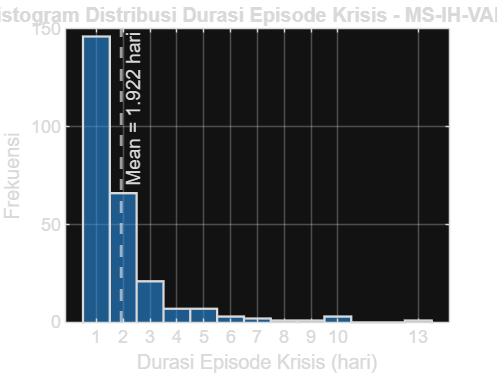


durasi = DurasiDistribusi.DurasiHari;
frekuensi = DurasiDistribusi.JumlahEpisode;
durasi_expanded = repelem(durasi, frekuensi);
mean_durasi = mean(durasi_expanded);

figure('Name','Histogram Durasi Episode Krisis','Color','w');
histogram(durasi_expanded, ...
    'BinEdges', 0.5:1:(max(durasi)+0.5), ...
    'LineWidth', 1.2);
hold on;
xline(mean_durasi, '--', ...
    ['Mean = ', num2str(mean_durasi, '%.3f'), ' hari'], ...
    'LineWidth', 1.5);
grid on;
xlabel('Durasi Episode Krisis (hari)');
ylabel('Frekuensi');
title(['Histogram Distribusi Durasi Episode Krisis - ', model_name]);
xticks(unique(durasi));
hold off;


% =========================================================
% INVESTIGASI ASET DOMINAN BERDASARKAN Z-SCORE
% =========================================================
T = Result_Regime;
T.Date = datetime(T.Date);
T.RegimeLabel = string(T.RegimeLabel);

idxPeriod = T.Date >= datetime(2017,1,1) & ...
            T.Date <= datetime(2025,12,31);

T = T(idxPeriod, :);

T.z_ihsg = (T.ihsg - mean(T.ihsg, 'omitnan')) ./ std(T.ihsg, 'omitnan');
T.z_gold = (T.gold - mean(T.gold, 'omitnan')) ./ std(T.gold, 'omitnan');
T.z_btc  = (T.btc  - mean(T.btc,  'omitnan')) ./ std(T.btc,  'omitnan');

isCrisis = T.RegimeLabel == "Krisis";

changeFlag = [true; isCrisis(2:end) ~= isCrisis(1:end-1)];
groupID = cumsum(changeFlag);

crisisGroups = unique(groupID(isCrisis));

EpisodeTable = table();

for i = 1:length(crisisGroups)

    g = crisisGroups(i);
    idxEpisode = groupID == g & isCrisis;

    startDate = min(T.Date(idxEpisode));
    endDate   = max(T.Date(idxEpisode));
    duration  = sum(idxEpisode);

    temp = table( ...
        g, ...
        startDate, ...
        endDate, ...
        duration, ...
        'VariableNames', {'EpisodeID','StartDate','EndDate','DurationDays'} ...
    );

    EpisodeTable = [EpisodeTable; temp];
end

durasiTarget = unique(EpisodeTable.DurationDays)';
assetNamesZ = ["IHSG", "Emas", "Bitcoin"];
assetListZ  = ["IHSG"; "Emas"; "Bitcoin"];

AllEpisodeDominant = table();
AllSummaryAsset = table();

for d = durasiTarget

    TargetEpisodes = EpisodeTable(EpisodeTable.DurationDays == d, :);

    if height(TargetEpisodes) == 0
        continue;
    end

    TargetInvestigation = table();

    for i = 1:height(TargetEpisodes)

        idxEpisode = T.Date >= TargetEpisodes.StartDate(i) & ...
                     T.Date <= TargetEpisodes.EndDate(i) & ...
                     T.RegimeLabel == "Krisis";

        temp = T(idxEpisode, { ...
            'Date','ihsg','gold','btc', ...
            'z_ihsg','z_gold','z_btc', ...
            'Prob_Regime1','Prob_Regime2','RegimeLabel'});

        temp.EpisodeID = repmat(TargetEpisodes.EpisodeID(i), height(temp), 1);
        temp.DurationDays = repmat(d, height(temp), 1);

        TargetInvestigation = [TargetInvestigation; temp];
    end

    if isempty(TargetInvestigation)
        continue;
    end

    TargetInvestigation = movevars(TargetInvestigation, ...
        {'EpisodeID','DurationDays'}, 'Before', 'Date');

    TargetDominant = table();

    for i = 1:height(TargetEpisodes)

        epID = TargetEpisodes.EpisodeID(i);
        idxEp = TargetInvestigation.EpisodeID == epID;

        Zepisode = abs([TargetInvestigation.z_ihsg(idxEp), ...
                        TargetInvestigation.z_gold(idxEp), ...
                        TargetInvestigation.z_btc(idxEp)]);

        [maxAbsZ, idxMaxLinear] = max(Zepisode, [], 'all', 'linear');
        [rowMax, colMax] = ind2sub(size(Zepisode), idxMaxLinear);

        dominantAsset = assetNamesZ(colMax);

        datesEp = TargetInvestigation.Date(idxEp);
        dominantDate = datesEp(rowMax);

        meanProb2 = mean(TargetInvestigation.Prob_Regime2(idxEp), 'omitnan');
        medianProb2 = median(TargetInvestigation.Prob_Regime2(idxEp), 'omitnan');
        maxProb2  = max(TargetInvestigation.Prob_Regime2(idxEp));

        temp = table( ...
            epID, ...
            TargetEpisodes.StartDate(i), ...
            TargetEpisodes.EndDate(i), ...
            d, ...
            dominantDate, ...
            dominantAsset, ...
            maxAbsZ, ...
            meanProb2, ...
            medianProb2, ...
            maxProb2, ...
            'VariableNames', {'EpisodeID','StartDate','EndDate','DurationDays', ...
            'DominantDate','DominantAsset','MaxAbsZ', ...
            'MeanProb_Regime2','MedianProb_Regime2','MaxProb_Regime2'} ...
        );

        TargetDominant = [TargetDominant; temp];
    end

    AllEpisodeDominant = [AllEpisodeDominant; TargetDominant];

    SummaryAssetTarget = table();

    for j = 1:length(assetListZ)

        aset = assetListZ(j);
        idx = TargetDominant.DominantAsset == aset;

        jumlah = sum(idx);
        persen = jumlah / height(TargetDominant) * 100;

        temp = table( ...
            d, ...
            aset, ...
            jumlah, ...
            persen, ...
            'VariableNames', {'DurasiHari','AsetDominan','JumlahEpisode','Persentase'} ...
        );

        SummaryAssetTarget = [SummaryAssetTarget; temp];
    end

    AllSummaryAsset = [AllSummaryAsset; SummaryAssetTarget];
end

disp('=== TABEL ASET DOMINAN SEMUA EPISODE KRISIS ===');

=== TABEL ASET DOMINAN SEMUA EPISODE KRISIS ===


disp(AllEpisodeDominant);

    EpisodeID    StartDate      EndDate      DurationDays    DominantDate    DominantAsset    MaxAbsZ    MeanProb_Regime2    MedianProb_Regime2    MaxProb_Regime2
    _________    __________    __________    ____________    ____________    _____________    _______    ________________    __________________    _______________

         3       2017-01-11    2017-01-11          1          2017-01-11       "Bitcoin"      3.3066         0.99993              0.99993              0.99993    
         5       2017-01-17    2017-01-17          1          2017-01-17       "Bitcoin"      1.9482         0.50548              0.50548              0.50548    
       


disp('=== RINGKASAN ASET DOMINAN PER DURASI EPISODE ===');

=== RINGKASAN ASET DOMINAN PER DURASI EPISODE ===


disp(AllSummaryAsset);

    DurasiHari    AsetDominan    JumlahEpisode    Persentase
    __________    ___________    _____________    __________

         1         "IHSG"             35            23.973  
         1         "Emas"             35            23.973  
         1         "Bitcoin"          76            52.055  
         2         "IHSG"             17            25.758  
         2         "Emas"             19            28.788  
         2         "Bitcoin"          30            45.455  
         3         "IHSG"              8            38.095  
         3         "Emas"              6            28.571  
         3         "Bitcoin"           7            33.333  
         4         "IHSG"              3            42.857  
         4         "Emas"              0                 0  
         4         "Bitcoin"           4            57.143  
         


SummaryDominantAll = table();

for j = 1:length(assetListZ)

    aset = assetListZ(j);
    idx = AllEpisodeDominant.DominantAsset == aset;

    jumlah = sum(idx);
    persen = jumlah / height(AllEpisodeDominant) * 100;

    temp = table( ...
        aset, ...
        jumlah, ...
        persen, ...
        'VariableNames', {'AsetDominan','JumlahEpisode','Persentase'} ...
    );

    SummaryDominantAll = [SummaryDominantAll; temp];
end

SummaryDominantAll = sortrows(SummaryDominantAll, 'JumlahEpisode', 'descend');

disp('=== RINGKASAN GABUNGAN ASET DOMINAN SELURUH EPISODE KRISIS ===');

=== RINGKASAN GABUNGAN ASET DOMINAN SELURUH EPISODE KRISIS ===


disp(SummaryDominantAll);

    AsetDominan    JumlahEpisode    Persentase
    ___________    _____________    __________

     "Bitcoin"          124           48.062  
     "IHSG"              72           27.907  
     "Emas"              62           24.031  



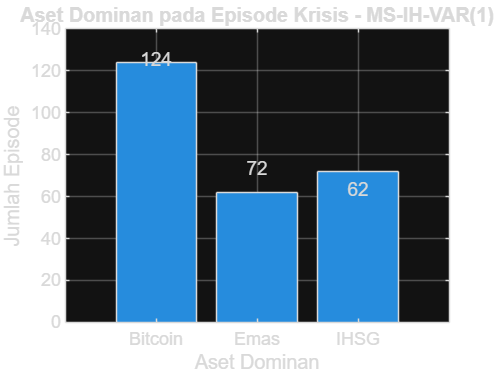


% Bar chart aset dominan
figure('Name','Aset Dominan Episode Krisis','Color','w');
bar(categorical(SummaryDominantAll.AsetDominan), SummaryDominantAll.JumlahEpisode);
grid on;
xlabel('Aset Dominan');
ylabel('Jumlah Episode');
title(['Aset Dominan pada Episode Krisis - ', model_name]);

for i = 1:height(SummaryDominantAll)
    text(i, SummaryDominantAll.JumlahEpisode(i)+1, ...
        num2str(SummaryDominantAll.JumlahEpisode(i)), ...
        'HorizontalAlignment','center');
end

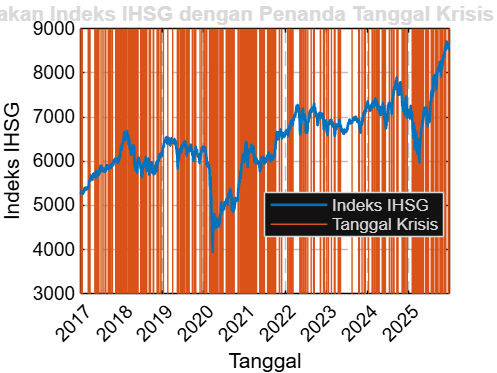

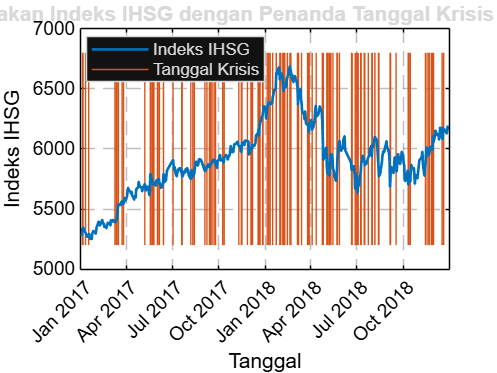

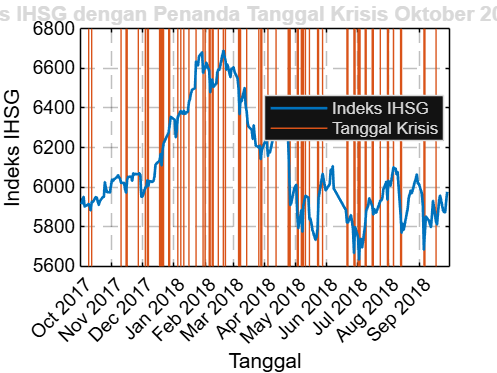

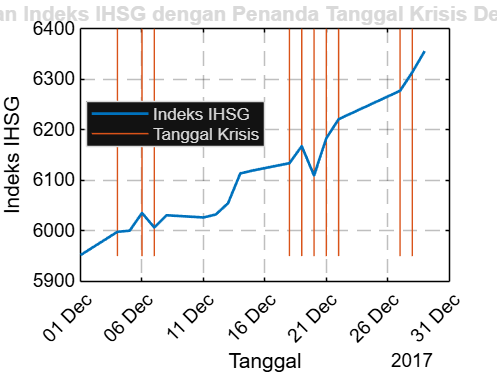

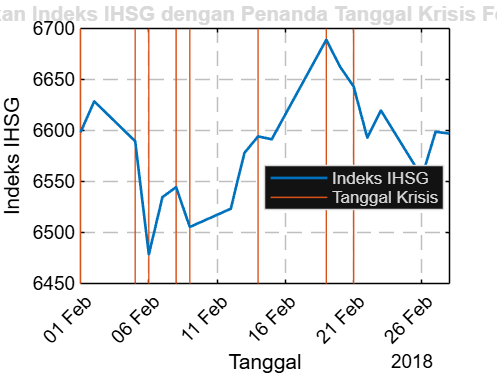

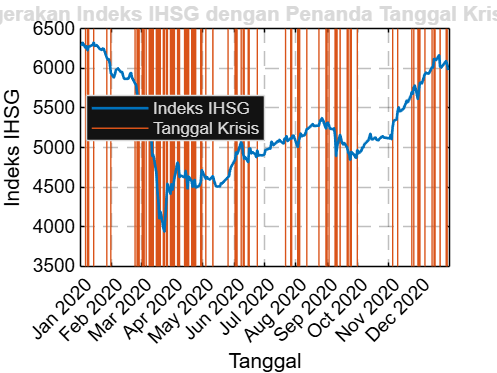

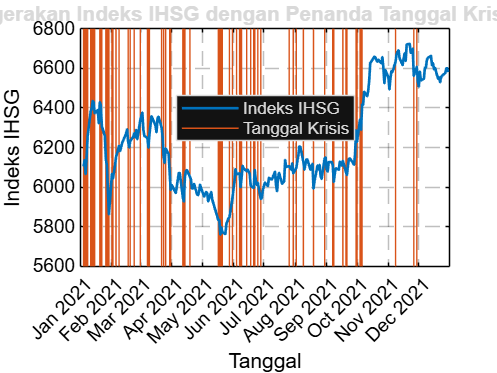

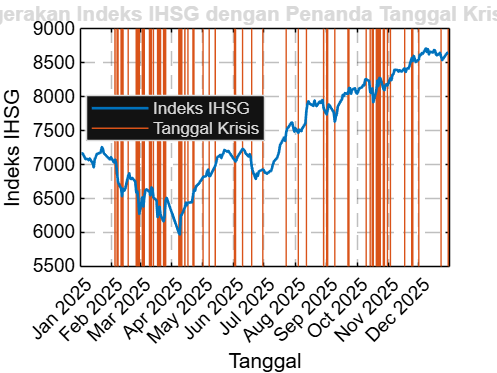

% =========================================================
% PLOT HARGA IHSG DENGAN PENANDA TANGGAL KRISIS
% =========================================================
try
    ihsgTbl = readtable('/MATLAB Drive/ihsg_daily.csv');
    ihsgTbl.Date = datetime(ihsgTbl.Date);

    % 2017-2025
    plotIHSGKrisis(ihsgTbl, Result_Regime, ...
        datetime(2017,1,1), datetime(2025,12,31), ...
        'Pergerakan Indeks IHSG dengan Penanda Tanggal Krisis 2017-2025');

    % 2017-2018
    plotIHSGKrisis(ihsgTbl, Result_Regime, ...
        datetime(2017,1,1), datetime(2018,12,31), ...
        'Pergerakan Indeks IHSG dengan Penanda Tanggal Krisis 2017-2018');

    % Oktober 2017 - September 2018
    plotIHSGKrisis(ihsgTbl, Result_Regime, ...
        datetime(2017,10,1), datetime(2018,9,30), ...
        'Pergerakan Indeks IHSG dengan Penanda Tanggal Krisis Oktober 2017 - September 2018');

    % Desember 2017
    plotIHSGKrisis(ihsgTbl, Result_Regime, ...
        datetime(2017,12,1), datetime(2017,12,31), ...
        'Pergerakan Indeks IHSG dengan Penanda Tanggal Krisis Desember 2017');

    % Februari 2018
    plotIHSGKrisis(ihsgTbl, Result_Regime, ...
        datetime(2018,2,1), datetime(2018,2,28), ...
        'Pergerakan Indeks IHSG dengan Penanda Tanggal Krisis Februari 2018');

    % 2020
    plotIHSGKrisis(ihsgTbl, Result_Regime, ...
        datetime(2020,1,1), datetime(2020,12,31), ...
        'Pergerakan Indeks IHSG dengan Penanda Tanggal Krisis 2020');

    % 2021
    plotIHSGKrisis(ihsgTbl, Result_Regime, ...
        datetime(2021,1,1), datetime(2021,12,31), ...
        'Pergerakan Indeks IHSG dengan Penanda Tanggal Krisis 2021');

    % 2025
    plotIHSGKrisis(ihsgTbl, Result_Regime, ...
        datetime(2025,1,1), datetime(2025,12,31), ...
        'Pergerakan Indeks IHSG dengan Penanda Tanggal Krisis 2025');

catch ME
    fprintf('\nPlot harga IHSG tidak dijalankan karena file ihsg_daily.csv tidak terbaca.\n');
    fprintf('Pesan error: %s\n', ME.message);
end


% =========================================================
% LOCAL FUNCTIONS
% Semua function harus berada di bagian paling bawah file.
% Jangan ada script utama lagi setelah bagian ini.
% =========================================================

function [InterceptByRegime, A, LagCoefByEq] = extract_MSIH_params(BestModel, K, p, M)

    InterceptByRegime = nan(K, M);
    A = zeros(K, K, p);
    LagCoefByEq = cell(K,1);

    for eqIdx = 1:K

        % -----------------------------
        % Ambil intercept switching
        % -----------------------------
        if isfield(BestModel.Coeff, 'S_Param')
            sp = BestModel.Coeff.S_Param{eqIdx};

            if isnumeric(sp)
                if isvector(sp)
                    spv = sp(:);

                    if numel(spv) >= M
                        InterceptByRegime(eqIdx,:) = spv(1:M)';
                    else
                        error('S_Param persamaan %d tidak memiliki %d intercept rezim.', eqIdx, M);
                    end

                elseif ismatrix(sp)
                    if size(sp,1) == M
                        InterceptByRegime(eqIdx,:) = sp(:,1)';
                    elseif size(sp,2) == M
                        InterceptByRegime(eqIdx,:) = sp(1,:);
                    else
                        error('Format S_Param persamaan %d tidak dikenali.', eqIdx);
                    end
                end
            else
                error('S_Param persamaan %d bukan numeric.', eqIdx);
            end
        else
            error('BestModel.Coeff.S_Param tidak ditemukan. Padahal model MS-IH membutuhkan intercept switching.');
        end

        % -----------------------------
        % Ambil lag non-switching
        % -----------------------------
        if isfield(BestModel.Coeff, 'nS_Param')
            ns = BestModel.Coeff.nS_Param{eqIdx}(:);

            if numel(ns) == K*p
                lagCoef = ns;
            elseif numel(ns) == 1 + K*p
                lagCoef = ns(2:end);
            else
                error('Jumlah nS_Param persamaan %d tidak sesuai. Ditemukan %d, seharusnya %d.', ...
                    eqIdx, numel(ns), K*p);
            end

            LagCoefByEq{eqIdx} = lagCoef;

            idx = 1;
            for L = 1:p
                for j = 1:K
                    A(eqIdx, j, L) = lagCoef(idx);
                    idx = idx + 1;
                end
            end

        else
            error('BestModel.Coeff.nS_Param tidak ditemukan.');
        end
    end
end


function plotIHSGKrisis(ihsgTbl, Result_Regime, startDate, endDate, figTitle)

    T = Result_Regime;
    T.Date = datetime(T.Date);
    T.RegimeLabel = string(T.RegimeLabel);

    % Ambil tanggal krisis sesuai rentang waktu
    idx_crisis = T.Date >= startDate & ...
                 T.Date <= endDate & ...
                 T.RegimeLabel == "Krisis";

    tanggal_crisis = T.Date(idx_crisis);

    % Ambil data IHSG sesuai rentang waktu
    idx_ihsg = ihsgTbl.Date >= startDate & ...
               ihsgTbl.Date <= endDate;

    ihsgPlot = ihsgTbl(idx_ihsg, :);

    tanggal_ihsg = ihsgPlot.Date;

    % Ambil kolom harga IHSG
    if ismember('ihsg', ihsgPlot.Properties.VariableNames)
        harga_ihsg = ihsgPlot.ihsg;
    elseif ismember('Close', ihsgPlot.Properties.VariableNames)
        harga_ihsg = ihsgPlot.Close;
    elseif ismember('AdjClose', ihsgPlot.Properties.VariableNames)
        harga_ihsg = ihsgPlot.AdjClose;
    else
        error('Kolom harga IHSG tidak ditemukan. Gunakan kolom ihsg, Close, atau AdjClose.');
    end

    % =====================================================
    % PLOT
    % =====================================================
    figure('Name', figTitle, 'Color', 'w');

    % Garis utama IHSG
    hIHSG = plot(tanggal_ihsg, harga_ihsg, ...
        'LineWidth', 1.4, ...
        'Color', [0 0.4470 0.7410]);

    hold on;
    grid on;

    yl = ylim;

    % Satu warna tetap untuk semua tanggal krisis
    crisisColor = [0.8500 0.3250 0.0980];

    % Dummy line untuk legend tanggal krisis
    hCrisis = plot(NaT, NaN, ...
        'Color', crisisColor, ...
        'LineWidth', 0.8);

    % Tambahkan garis vertikal tanggal krisis
    for i = 1:length(tanggal_crisis)
        line([tanggal_crisis(i) tanggal_crisis(i)], yl, ...
            'Color', crisisColor, ...
            'LineStyle', '-', ...
            'LineWidth', 0.35, ...
            'HandleVisibility', 'off');
    end

    % Plot ulang IHSG supaya garis biru berada di atas garis krisis
    plot(tanggal_ihsg, harga_ihsg, ...
        'LineWidth', 1.4, ...
        'Color', [0 0.4470 0.7410], ...
        'HandleVisibility', 'off');

    % =====================================================
    % FORMAT X-AXIS BERDASARKAN RENTANG WAKTU
    % =====================================================
    xlim([startDate endDate]);

    rangeDays = days(endDate - startDate);

    if rangeDays <= 40
        xticks(startDate:caldays(5):endDate);
        xtickformat('dd MMM');
    elseif rangeDays <= 400
        xticks(dateshift(startDate,'start','month'):calmonths(1):dateshift(endDate,'start','month'));
        xtickformat('MMM yyyy');
    elseif rangeDays <= 800
        xticks(dateshift(startDate,'start','month'):calmonths(3):dateshift(endDate,'start','month'));
        xtickformat('MMM yyyy');
    else
        xticks(datetime(year(startDate):year(endDate),1,1));
        xtickformat('yyyy');
    end

    xtickangle(45);

    xlabel('Tanggal');
    ylabel('Indeks IHSG');
    title(figTitle);

    legend([hIHSG hCrisis], {'Indeks IHSG','Tanggal Krisis'}, ...
        'Location','best');

    ax = gca;
    ax.Color = 'w';
    ax.XColor = 'k';
    ax.YColor = 'k';
    ax.GridLineStyle = '--';
    ax.GridAlpha = 0.25;
    ax.FontSize = 10;

    hold off;

end

% =========================================================
% TAMPILKAN HASIL KLASIFIKASI HARIAN DI OUTPUT MATLAB
% MS-IH-VAR(1)
% =========================================================

T_class = Result_Regime;
T_class.Date = datetime(T_class.Date);

% Tambahkan kolom tahun dan bulan
T_class.Year  = year(T_class.Date);
T_class.Month = month(T_class.Date);

% Susun tabel hasil klasifikasi harian
DailyClassification = T_class(:, { ...
    'Date', ...
    'Year', ...
    'Month', ...
    'ihsg', ...
    'gold', ...
    'btc', ...
    'Prob_Regime1', ...
    'Prob_Regime2', ...
    'MostLikelyRegime', ...
    'RegimeLabel'});

% Ubah nama kolom agar rapi
DailyClassification.Properties.VariableNames = { ...
    'Date', ...
    'Year', ...
    'Month', ...
    'Return_IHSG', ...
    'Return_Gold', ...
    'Return_BTC', ...
    'Prob_Regime1', ...
    'Prob_Regime2', ...
    'MostLikelyRegime', ...
    'RegimeLabel'};

% =========================================================
% TAMPILKAN HASIL DI COMMAND WINDOW
% =========================================================

disp('=========================================================');

disp('HASIL KLASIFIKASI HARIAN MS-IH-VAR(1)');

HASIL KLASIFIKASI HARIAN MS-IH-VAR(1)


disp('=========================================================');

disp(DailyClassification);

       Date       Year    Month    Return_IHSG    Return_Gold    Return_BTC    Prob_Regime1    Prob_Regime2    MostLikelyRegime    RegimeLabel
    __________    ____    _____    ___________    ___________    __________    ____________    ____________    ________________    ___________

    2017-01-05    2017      1          0.45772       0.16488        -14.579     5.0548e-06        0.99999             2             "Krisis"  
    2017-01-06    2017      1          0.40328      -0.16488        -11.178       0.001061        0.99894             2             "Krisis"  
    2017-01-09    2017      1         -0.57505      -0.66225         1.8073        0.91


fprintf('\nJumlah observasi klasifikasi harian: %d hari\n', height(DailyClassification));


Jumlah observasi klasifikasi harian: 2345 hari


fprintf('Tanggal awal efektif : %s\n', datestr(DailyClassification.Date(1), 'dd-mmm-yyyy'));

Tanggal awal efektif : 05-Jan-2017


fprintf('Tanggal akhir        : %s\n', datestr(DailyClassification.Date(end), 'dd-mmm-yyyy'));

Tanggal akhir        : 31-Dec-2025


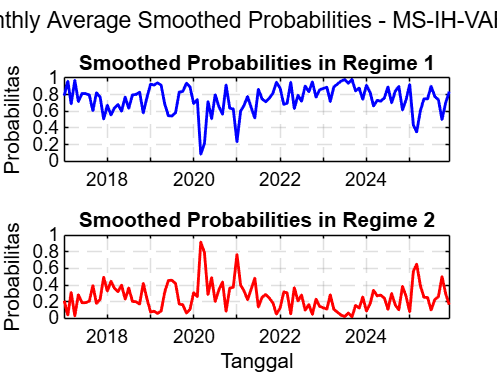

% =========================================================
% PLOT SMOOTHED PROBABILITIES RATA-RATA BULANAN 
% =========================================================

dates_eff  = dates_eff(:);
smoothProb = smoothProb(1:length(dates_eff), :);

TT = timetable(dates_eff, smoothProb(:,1), smoothProb(:,2), ...
    'VariableNames', {'Regime1','Regime2'});

TT_monthly = retime(TT, 'monthly', 'mean');

monthlyDates = TT_monthly.dates_eff;

figure('Name','Monthly Smoothed Probabilities','Color','w');

% =========================================================
% SUBPLOT 1: REGIME 1
% =========================================================
subplot(2,1,1);

plot(monthlyDates, TT_monthly.Regime1, ...
    'b', ...
    'LineWidth', 1.5);

ylim([0 1]);
yticks(0:0.2:1);
xlim([min(monthlyDates) max(monthlyDates)]);
grid on;

ylabel('Probabilitas', 'Color', 'k');
title('Smoothed Probabilities in Regime 1', 'Color', 'k');

ax = gca;
ax.Color = 'w';
ax.XColor = 'k';
ax.YColor = 'k';
ax.GridColor = [0.5 0.5 0.5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.25;
ax.FontSize = 10;
xtickformat('yyyy');

% =========================================================
% SUBPLOT 2: REGIME 2
% =========================================================
subplot(2,1,2);

plot(monthlyDates, TT_monthly.Regime2, ...
    'r', ...
    'LineWidth', 1.5);

ylim([0 1]);
yticks(0:0.2:1);
xlim([min(monthlyDates) max(monthlyDates)]);
grid on;

xlabel('Tanggal', 'Color', 'k');
ylabel('Probabilitas', 'Color', 'k');
title('Smoothed Probabilities in Regime 2', 'Color', 'k');

ax = gca;
ax.Color = 'w';
ax.XColor = 'k';
ax.YColor = 'k';
ax.GridColor = [0.5 0.5 0.5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.25;
ax.FontSize = 10;
xtickformat('yyyy');

% =========================================================
% JUDUL UTAMA
% =========================================================
sgtitle(['Monthly Average Smoothed Probabilities - ', model_name], ...
    'Color', 'k');

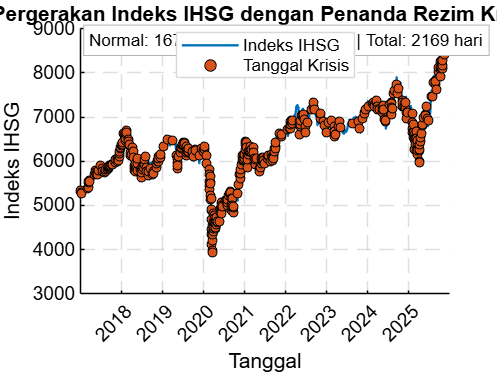

% =========================================================
% PLOT LEVEL IHSG DENGAN TITIK KRISIS SAJA
% =========================================================

try
    ihsgTbl = readtable('/MATLAB Drive/ihsg_daily.csv');
    ihsgTbl.Date = datetime(ihsgTbl.Date);

    % Ambil kolom harga IHSG
    if ismember('ihsg', ihsgTbl.Properties.VariableNames)
        harga_ihsg_all = ihsgTbl.ihsg;
    elseif ismember('Close', ihsgTbl.Properties.VariableNames)
        harga_ihsg_all = ihsgTbl.Close;
    elseif ismember('AdjClose', ihsgTbl.Properties.VariableNames)
        harga_ihsg_all = ihsgTbl.AdjClose;
    else
        error('Kolom harga IHSG tidak ditemukan. Gunakan kolom ihsg, Close, atau AdjClose.');
    end

    % Samakan tanggal IHSG level dengan tanggal efektif model
    [isMatch, loc] = ismember(dates_eff, ihsgTbl.Date);

    dates_plot      = dates_eff(isMatch);
    regime_plot     = regimePath(isMatch);
    harga_ihsg_plot = harga_ihsg_all(loc(isMatch));

    % Ambil krisis saja
    idx_crisis = regime_plot == crisisRegime;
    idx_normal = regime_plot == normalRegime;

    dates_crisis = dates_plot(idx_crisis);
    harga_crisis = harga_ihsg_plot(idx_crisis);

    % =====================================================
    % PLOT
    % =====================================================
    figure('Name','IHSG Level dengan Titik Krisis','Color','w');
    hold on;

    % Garis utama IHSG
    hIHSG = plot(dates_plot, harga_ihsg_plot, '-', ...
        'LineWidth', 1.2, ...
        'Color', [0 0.4470 0.7410]);

    % Titik krisis saja
    hCrisis = scatter(dates_crisis, harga_crisis, ...
        22, ...
        [0.8500 0.3250 0.0980], ...
        'filled', ...
        'MarkerEdgeColor', 'k', ...
        'LineWidth', 0.25);

    grid on;

    xlabel('Tanggal', 'Color', 'k');
    ylabel('Indeks IHSG', 'Color', 'k');
    title('Pergerakan Indeks IHSG dengan Penanda Rezim Krisis', 'Color', 'k');

    legend([hIHSG hCrisis], {'Indeks IHSG','Tanggal Krisis'}, ...
        'Location','best', ...
        'TextColor','k', ...
        'Color','w');

    ax = gca;
    ax.Color = 'w';
    ax.XColor = 'k';
    ax.YColor = 'k';
    ax.GridColor = [0.5 0.5 0.5];
    ax.GridLineStyle = '--';
    ax.GridAlpha = 0.25;
    ax.FontSize = 10;

    xlim([min(dates_plot) max(dates_plot)]);
    xticks(datetime(year(min(dates_plot)):year(max(dates_plot)),1,1));
    xtickformat('yyyy');
    xtickangle(45);

    % Tambahkan informasi jumlah observasi
    nNormal = sum(idx_normal);
    nKrisis = sum(idx_crisis);
    nTotal  = length(regime_plot);

    infoText = sprintf('Normal: %d hari | Krisis: %d hari | Total: %d hari', ...
        nNormal, nKrisis, nTotal);

    text(0.02, 0.95, infoText, ...
        'Units','normalized', ...
        'FontSize', 9, ...
        'Color','k', ...
        'BackgroundColor','w', ...
        'EdgeColor',[0.7 0.7 0.7]);

    hold off;

catch ME
    fprintf('\nPlot IHSG dengan titik krisis tidak dijalankan.\n');
    fprintf('Pesan error: %s\n', ME.message);
end

% =========================================================
% JUMLAH HARI KRISIS SETIAP BULAN BERDASARKAN HASIL MODEL
% =========================================================

T = Result_Regime;
T.Date = datetime(T.Date);
T.RegimeLabel = string(T.RegimeLabel);

% Tentukan indikator krisis
T.IsCrisis = T.RegimeLabel == "Krisis";

% Buat variabel tahun dan bulan
T.Year = year(T.Date);
T.Month = month(T.Date);
T.YearMonth = dateshift(T.Date, 'start', 'month');

% Ambil daftar bulan unik
uniqueMonth = unique(T.YearMonth);

MonthlyCrisis = table();

for i = 1:length(uniqueMonth)

    ym = uniqueMonth(i);
    idxMonth = T.YearMonth == ym;

    tahun = year(ym);
    bulan = month(ym);
    namaBulan = string(month(ym, 'name'));

    totalHariObservasi = sum(idxMonth);
    totalHariKrisis = sum(T.IsCrisis(idxMonth));
    totalHariNormal = totalHariObservasi - totalHariKrisis;

    persentaseKrisis = totalHariKrisis / totalHariObservasi * 100;

    temp = table( ...
        tahun, ...
        bulan, ...
        namaBulan, ...
        totalHariObservasi, ...
        totalHariNormal, ...
        totalHariKrisis, ...
        persentaseKrisis, ...
        'VariableNames', {'Tahun','Bulan','NamaBulan', ...
        'TotalHariObservasi','TotalHariNormal','TotalHariKrisis','PersentaseKrisis'} ...
        );

    MonthlyCrisis = [MonthlyCrisis; temp];
end

disp('=== JUMLAH HARI KRISIS SETIAP BULAN ===');

=== JUMLAH HARI KRISIS SETIAP BULAN ===


disp(MonthlyCrisis);

    Tahun    Bulan     NamaBulan     TotalHariObservasi    TotalHariNormal    TotalHariKrisis    PersentaseKrisis
    _____    _____    ___________    __________________    _______________    _______________    ________________

    2017       1      "January"              19                  15                  4                21.053     
    2017       2      "February"             20                  20                  0                     0     
    2017       3      "March"                23                  17                  6                26.087     
    2017       4      "April"                20                  20                  0                     0     
    2017       5      "May"                  23                  17          


% =========================================================
% CEK TOTAL
% =========================================================
fprintf('\n=== CEK TOTAL KRISIS ===\n');


=== CEK TOTAL KRISIS ===


fprintf('Total hari krisis dari tabel bulanan : %d hari\n', sum(MonthlyCrisis.TotalHariKrisis));

Total hari krisis dari tabel bulanan : 496 hari


fprintf('Total hari krisis dari Result_Regime : %d hari\n', sum(T.IsCrisis));

Total hari krisis dari Result_Regime : 496 hari


% =========================================================
% JUMLAH HARI KRISIS SETIAP TAHUN BERDASARKAN HASIL MODEL
% =========================================================

T = Result_Regime;
T.Date = datetime(T.Date);
T.RegimeLabel = string(T.RegimeLabel);

% Tentukan indikator krisis
T.IsCrisis = T.RegimeLabel == "Krisis";

% Buat variabel tahun
T.Year = year(T.Date);

% Ambil daftar tahun unik
uniqueYear = unique(T.Year);

YearlyCrisis = table();

for i = 1:length(uniqueYear)

    tahun = uniqueYear(i);
    idxYear = T.Year == tahun;

    totalHariObservasi = sum(idxYear);
    totalHariKrisis = sum(T.IsCrisis(idxYear));
    totalHariNormal = totalHariObservasi - totalHariKrisis;

    persentaseKrisis = totalHariKrisis / totalHariObservasi * 100;

    temp = table( ...
        tahun, ...
        totalHariObservasi, ...
        totalHariNormal, ...
        totalHariKrisis, ...
        persentaseKrisis, ...
        'VariableNames', {'Tahun', ...
        'TotalHariObservasi','TotalHariNormal','TotalHariKrisis','PersentaseKrisis'} ...
        );

    YearlyCrisis = [YearlyCrisis; temp];
end

disp('=== JUMLAH HARI KRISIS SETIAP TAHUN ===');

=== JUMLAH HARI KRISIS SETIAP TAHUN ===


disp(YearlyCrisis);

    Tahun    TotalHariObservasi    TotalHariNormal    TotalHariKrisis    PersentaseKrisis
    _____    __________________    _______________    _______________    ________________

    2017            257                  207                50                19.455     
    2018            261                  192                69                26.437     
    2019            261                  218                43                16.475     
    2020            262                  168                94                35.878     
    2021            261                  188                73                27.969     
    2022            260                  225                35                13.462     
    2023            260                  241                19                7.3077     
    2024           


% =========================================================
% CEK TOTAL
% =========================================================
fprintf('\n=== CEK TOTAL KRISIS ===\n');


=== CEK TOTAL KRISIS ===


fprintf('Total hari krisis dari tabel tahunan : %d hari\n', sum(YearlyCrisis.TotalHariKrisis));

Total hari krisis dari tabel tahunan : 496 hari


fprintf('Total hari krisis dari Result_Regime : %d hari\n', sum(T.IsCrisis));

Total hari krisis dari Result_Regime : 496 hari



% =========================================================
% URUTKAN TAHUN DENGAN HARI KRISIS TERBANYAK
% =========================================================

YearlyCrisisRank = sortrows(YearlyCrisis, 'TotalHariKrisis', 'descend');

disp('=== TAHUN DENGAN HARI KRISIS TERBANYAK ===');

=== TAHUN DENGAN HARI KRISIS TERBANYAK ===


disp(YearlyCrisisRank);

    Tahun    TotalHariObservasi    TotalHariNormal    TotalHariKrisis    PersentaseKrisis
    _____    __________________    _______________    _______________    ________________

    2020            262                  168                94                35.878     
    2021            261                  188                73                27.969     
    2018            261                  192                69                26.437     
    2025            261                  192                69                26.437     
    2017            257                  207                50                19.455     
    2024            262                  218                44                16.794     
    2019            261                  218                43                16.475     
    2022           

% =========================================================
% ANALISIS KECENDERUNGAN KRISIS BULANAN
% Berdasarkan:
% 1. Persentase hari krisis per bulan
% 2. Rata-rata probabilitas krisis bulanan
% =========================================================

T = Result_Regime;
T.Date = datetime(T.Date);
T.RegimeLabel = string(T.RegimeLabel);

% =========================================================
% TENTUKAN KOLOM PROBABILITAS KRISIS
% =========================================================
% Jika crisisRegime = 1, maka probabilitas krisis = Prob_Regime1
% Jika crisisRegime = 2, maka probabilitas krisis = Prob_Regime2

if crisisRegime == 1
    T.ProbKrisis = T.Prob_Regime1;
elseif crisisRegime == 2
    T.ProbKrisis = T.Prob_Regime2;
else
    error('crisisRegime harus bernilai 1 atau 2.');
end

% Indikator krisis harian
T.IsCrisis = T.RegimeLabel == "Krisis";

% Tahun dan bulan
T.YearMonth = dateshift(T.Date, 'start', 'month');

% Daftar bulan unik
uniqueMonth = unique(T.YearMonth);

MonthlyCrisisProb = table();

for i = 1:length(uniqueMonth)

    ym = uniqueMonth(i);
    idxMonth = T.YearMonth == ym;

    tahun = year(ym);
    bulan = month(ym);
    namaBulan = string(month(ym, 'name'));

    totalHariObservasi = sum(idxMonth);
    totalHariKrisis = sum(T.IsCrisis(idxMonth));
    totalHariNormal = totalHariObservasi - totalHariKrisis;

    persentaseHariKrisis = totalHariKrisis / totalHariObservasi * 100;

    meanProbKrisis = mean(T.ProbKrisis(idxMonth), 'omitnan');
    medianProbKrisis = median(T.ProbKrisis(idxMonth), 'omitnan');
    maxProbKrisis = max(T.ProbKrisis(idxMonth));
    minProbKrisis = min(T.ProbKrisis(idxMonth));

    temp = table( ...
        ym, ...
        tahun, ...
        bulan, ...
        namaBulan, ...
        totalHariObservasi, ...
        totalHariNormal, ...
        totalHariKrisis, ...
        persentaseHariKrisis, ...
        meanProbKrisis, ...
        medianProbKrisis, ...
        maxProbKrisis, ...
        minProbKrisis, ...
        'VariableNames', {'YearMonth','Tahun','Bulan','NamaBulan', ...
        'TotalHariObservasi','TotalHariNormal','TotalHariKrisis', ...
        'PersentaseHariKrisis','MeanProbKrisis','MedianProbKrisis', ...
        'MaxProbKrisis','MinProbKrisis'} ...
    );

    MonthlyCrisisProb = [MonthlyCrisisProb; temp];
end

disp('=== ANALISIS KECENDERUNGAN KRISIS BULANAN ===');

=== ANALISIS KECENDERUNGAN KRISIS BULANAN ===


disp(MonthlyCrisisProb);

    YearMonth     Tahun    Bulan     NamaBulan     TotalHariObservasi    TotalHariNormal    TotalHariKrisis    PersentaseHariKrisis    MeanProbKrisis    MedianProbKrisis    MaxProbKrisis    MinProbKrisis
    __________    _____    _____    ___________    __________________    _______________    _______________    ____________________    ______________    ________________    _____________    _____________

    2017-01-01    2017       1      "January"              19                  15                  4                  21.053               0.21261            0.03291           0.99999


% =========================================================
% URUTKAN BERDASARKAN PERSENTASE HARI KRISIS TERTINGGI
% =========================================================

MonthlyCrisisRank_ByDays = sortrows(MonthlyCrisisProb, ...
    'PersentaseHariKrisis', 'descend');

disp('=== RANKING BULAN BERDASARKAN PERSENTASE HARI KRISIS ===');

=== RANKING BULAN BERDASARKAN PERSENTASE HARI KRISIS ===


disp(MonthlyCrisisRank_ByDays);

    YearMonth     Tahun    Bulan     NamaBulan     TotalHariObservasi    TotalHariNormal    TotalHariKrisis    PersentaseHariKrisis    MeanProbKrisis    MedianProbKrisis    MaxProbKrisis    MinProbKrisis
    __________    _____    _____    ___________    __________________    _______________    _______________    ____________________    ______________    ________________    _____________    _____________

    2020-03-01    2020       3      "March"                22                   2                 20                  90.909                0.9157            0.99998                 1


% =========================================================
% URUTKAN BERDASARKAN RATA-RATA PROBABILITAS KRISIS TERTINGGI
% =========================================================

MonthlyCrisisRank_ByProb = sortrows(MonthlyCrisisProb, ...
    'MeanProbKrisis', 'descend');

disp('=== RANKING BULAN BERDASARKAN RATA-RATA PROBABILITAS KRISIS ===');

=== RANKING BULAN BERDASARKAN RATA-RATA PROBABILITAS KRISIS ===


disp(MonthlyCrisisRank_ByProb);

    YearMonth     Tahun    Bulan     NamaBulan     TotalHariObservasi    TotalHariNormal    TotalHariKrisis    PersentaseHariKrisis    MeanProbKrisis    MedianProbKrisis    MaxProbKrisis    MinProbKrisis
    __________    _____    _____    ___________    __________________    _______________    _______________    ____________________    ______________    ________________    _____________    _____________

    2020-03-01    2020       3      "March"                22                   2                 20                  90.909                0.9157            0.99998                 1


% =========================================================
% OPSIONAL: KLASIFIKASI BULAN DOMINAN KRISIS
% Jika lebih dari 50% hari observasi dalam bulan tersebut adalah krisis
% =========================================================

MonthlyCrisisProb.DominasiKrisis = MonthlyCrisisProb.PersentaseHariKrisis > 50;

disp('=== BULAN DENGAN DOMINASI HARI KRISIS > 50% ===');

=== BULAN DENGAN DOMINASI HARI KRISIS > 50% ===


disp(MonthlyCrisisProb(MonthlyCrisisProb.DominasiKrisis == true, :));

    YearMonth     Tahun    Bulan    NamaBulan     TotalHariObservasi    TotalHariNormal    TotalHariKrisis    PersentaseHariKrisis    MeanProbKrisis    MedianProbKrisis    MaxProbKrisis    MinProbKrisis    DominasiKrisis
    __________    _____    _____    __________    __________________    _______________    _______________    ____________________    ______________    ________________    _____________    _____________    ______________

    2020-03-01    2020       3      "March"               22                   2                 20                


% =========================================================
% CEK TOTAL
% =========================================================

fprintf('\n=== CEK TOTAL KRISIS ===\n');


=== CEK TOTAL KRISIS ===


fprintf('Total hari krisis dari tabel bulanan : %d hari\n', sum(MonthlyCrisisProb.TotalHariKrisis));

Total hari krisis dari tabel bulanan : 496 hari


fprintf('Total hari krisis dari Result_Regime : %d hari\n', sum(T.IsCrisis));

Total hari krisis dari Result_Regime : 496 hari


% =========================================================
% FITTED VALUE DAN RESIDUAL MS-IH-VAR(1) PER REZIM
% =========================================================
% Struktur model:
% y_t = v(m) + A_1 y_(t-1) + u_t(m)
%
% Karena model yang digunakan adalah MS-IH-VAR(1):
% - Intercept v(m) berbeda antar rezim
% - Koefisien A_1 tidak berbeda antar rezim
% - Varians-kovarians Sigma(m) berbeda antar rezim
%
% Output bagian ini:
% 1. Prediksi y_t untuk rezim 1 dan rezim 2
% 2. Residual u_t untuk rezim 1 dan rezim 2
% 3. Prediksi dan residual berdasarkan most likely regime
% 4. Prediksi dan residual berbobot probabilitas rezim
% =========================================================

% Samakan panjang seluruh komponen
nObsFit = min([ ...
    length(dates_eff), ...
    size(dep,1), ...
    size(Xlag,1), ...
    size(smoothProb,1), ...
    length(regimePath) ...
]);

dates_fit  = dates_eff(1:nObsFit);
Y_actual   = dep(1:nObsFit, :);
Xlag_fit   = Xlag(1:nObsFit, :);
prob_fit   = smoothProb(1:nObsFit, :);
regime_fit = regimePath(1:nObsFit);

% Jumlah rezim
nState = k;

% Mu_byRegime(:,:,m) = prediksi y_t jika observasi t dianggap berada pada rezim m
Mu_byRegime = nan(nObsFit, nVar, nState);

for m = 1:nState

    % Komponen intercept rezim ke-m
    mu_m = repmat(InterceptByRegime(:,m)', nObsFit, 1);

    % Komponen autoregresif
    for L = 1:nLag
        colsL = (L-1)*nVar + (1:nVar);
        YlagL = Xlag_fit(:, colsL);

        % A(:,:,L) berukuran nVar x nVar
        % YlagL berukuran nObsFit x nVar
        % sehingga digunakan transpose agar hasil akhir nObsFit x nVar
        mu_m = mu_m + YlagL * A(:,:,L)';
    end

    Mu_byRegime(:,:,m) = mu_m;
end

% =========================================================
% RESIDUAL KONDISIONAL PER REZIM
% u_t(m) = y_t - yhat_t(m)
% =========================================================

Resid_byRegime = nan(nObsFit, nVar, nState);

for m = 1:nState
    Resid_byRegime(:,:,m) = Y_actual - Mu_byRegime(:,:,m);
end

% =========================================================
% PREDIKSI DAN RESIDUAL BERDASARKAN MOST LIKELY REGIME
% =========================================================

Yhat_selected  = nan(nObsFit, nVar);
Resid_selected = nan(nObsFit, nVar);

for t = 1:nObsFit
    m = regime_fit(t);

    Yhat_selected(t,:)  = Mu_byRegime(t,:,m);
    Resid_selected(t,:) = Resid_byRegime(t,:,m);
end

% =========================================================
% PREDIKSI DAN RESIDUAL BERBOBOT PROBABILITAS REZIM
% yhat_t = Prob(R1)*yhat_t(1) + Prob(R2)*yhat_t(2)
% =========================================================

Yhat_weighted = zeros(nObsFit, nVar);

for m = 1:nState
    Yhat_weighted = Yhat_weighted + bsxfun(@times, prob_fit(:,m), Mu_byRegime(:,:,m));
end

Resid_weighted = Y_actual - Yhat_weighted;

% =========================================================
% TABEL HASIL HARIAN
% =========================================================

Prediction_MSVAR_Daily = table( ...
    dates_fit, ...
    Y_actual(:,1), Y_actual(:,2), Y_actual(:,3), ...
    prob_fit(:,1), prob_fit(:,2), ...
    regime_fit, ...
    Mu_byRegime(:,1,1), Mu_byRegime(:,2,1), Mu_byRegime(:,3,1), ...
    Resid_byRegime(:,1,1), Resid_byRegime(:,2,1), Resid_byRegime(:,3,1), ...
    Mu_byRegime(:,1,2), Mu_byRegime(:,2,2), Mu_byRegime(:,3,2), ...
    Resid_byRegime(:,1,2), Resid_byRegime(:,2,2), Resid_byRegime(:,3,2), ...
    Yhat_selected(:,1), Yhat_selected(:,2), Yhat_selected(:,3), ...
    Resid_selected(:,1), Resid_selected(:,2), Resid_selected(:,3), ...
    Yhat_weighted(:,1), Yhat_weighted(:,2), Yhat_weighted(:,3), ...
    Resid_weighted(:,1), Resid_weighted(:,2), Resid_weighted(:,3), ...
    'VariableNames', { ...
    'Date', ...
    'Actual_IHSG','Actual_Gold','Actual_BTC', ...
    'Prob_Regime1','Prob_Regime2', ...
    'MostLikelyRegime', ...
    'Pred_IHSG_R1','Pred_Gold_R1','Pred_BTC_R1', ...
    'Resid_IHSG_R1','Resid_Gold_R1','Resid_BTC_R1', ...
    'Pred_IHSG_R2','Pred_Gold_R2','Pred_BTC_R2', ...
    'Resid_IHSG_R2','Resid_Gold_R2','Resid_BTC_R2', ...
    'Pred_IHSG_Selected','Pred_Gold_Selected','Pred_BTC_Selected', ...
    'Resid_IHSG_Selected','Resid_Gold_Selected','Resid_BTC_Selected', ...
    'Pred_IHSG_Weighted','Pred_Gold_Weighted','Pred_BTC_Weighted', ...
    'Resid_IHSG_Weighted','Resid_Gold_Weighted','Resid_BTC_Weighted'} ...
);

disp('=== TABEL PREDIKSI DAN RESIDUAL MS-VAR HARIAN ===');

=== TABEL PREDIKSI DAN RESIDUAL MS-VAR HARIAN ===


disp(head(Prediction_MSVAR_Daily, 10));

       Date       Actual_IHSG    Actual_Gold    Actual_BTC    Prob_Regime1    Prob_Regime2    MostLikelyRegime    Pred_IHSG_R1    Pred_Gold_R1    Pred_BTC_R1    Resid_IHSG_R1    Resid_Gold_R1    Resid_BTC_R1    Pred_IHSG_R2    Pred_Gold_R2    Pred_BTC_R2    Resid_IHSG_R2    Resid_Gold_R2    Resid_BTC_R2    Pred_IHSG_Selected    Pred_Gold_Selected    Pred_BTC_Selected    Resid_IHSG_Selected    Resid_Gold_Selected    Resid_BTC_Selected    Pred_IHSG_Weighted    Pred_Gold_Weighted    Pred_BTC_Weighted    Resid_IHSG


% =========================================================
% CEK UKURAN OUTPUT
% =========================================================

fprintf('\n=== UKURAN OUTPUT PREDIKSI DAN RESIDUAL ===\n');


=== UKURAN OUTPUT PREDIKSI DAN RESIDUAL ===


fprintf('Jumlah observasi harian : %d\n', height(Prediction_MSVAR_Daily));

Jumlah observasi harian : 2345


fprintf('Jumlah variabel         : %d\n', nVar);

Jumlah variabel         : 3


fprintf('Jumlah rezim            : %d\n', nState);

Jumlah rezim            : 2



fprintf('\nUkuran Mu_byRegime      : %d x %d x %d\n', ...
    size(Mu_byRegime,1), size(Mu_byRegime,2), size(Mu_byRegime,3));


Ukuran Mu_byRegime      : 2345 x 3 x 2



fprintf('Ukuran Resid_byRegime   : %d x %d x %d\n', ...
    size(Resid_byRegime,1), size(Resid_byRegime,2), size(Resid_byRegime,3));

Ukuran Resid_byRegime   : 2345 x 3 x 2


idx_2017 = Result_Regime.Date >= datetime(2017,1,1) & ...
    Result_Regime.Date <= datetime(2017,12,31);
Result_Regime_2017 = Result_Regime(idx_2017, :);
disp(Result_Regime_2017);

       Date          ihsg         gold         btc       Prob_Regime1    Prob_Regime2    MostLikelyRegime    RegimeLabel
    __________    __________    ________    _________    ____________    ____________    ________________    ___________

    2017-01-05       0.45772     0.16488      -14.579     5.0548e-06        0.99999             2             "Krisis"  
    2017-01-06       0.40328    -0.16488      -11.178       0.001061        0.99894             2             "Krisis"  
    2017-01-09      -0.57505    -0.66225       1.8073        0.91225        0.08775             1             "Normal"  
    2017-01-10      -0.12121      0.4971     0.023121          0.935       0.064999             1             "Normal"  
 

idx_2025 = Result_Regime.Date >= datetime(2025,1,1) & ...
    Result_Regime.Date <= datetime(2025,12,31);
Result_Regime_2025 = Result_Regime(idx_2025, :);
disp(Result_Regime_2025);

       Date         ihsg         gold          btc       Prob_Regime1    Prob_Regime2    MostLikelyRegime    RegimeLabel
    __________    _________    _________    _________    ____________    ____________    ________________    ___________

    2025-01-01            0            0            0        0.98923       0.010771             1             "Normal"  
    2025-01-02       1.1698     -0.26212       3.8269        0.88855        0.11145             1             "Normal"  
    2025-01-03      0.01703        1.239       1.7254         0.8814         0.1186             1             "Normal"  
    2025-01-06      -1.1788     -0.25957       3.9562        0.82472        0.17528             1             "Normal"  
 